## Source reconstruction

Mathilde Marie Duville

**Notice:** please, run the codes for figures in the command window to output them with a correct scale for visualization

### General concepts

- The head model describes how the neuronal activity propagates through the skull and scalp. It reflects the geometrical (mesh) and conductive properties of the head.

- The source model describes the position of the sources that generate the activity. It is a matrix of size m neural sources * k samples (or y*x*z*k).

- The positions of the sensors must be aligned with both the head and the source models. 

*Forward modelling* (i.e., how activity of the sources propagate into the sensors) can be computed from those three components. From the forward model, the** leadfield matrix** of size n sensors*x*y*z (or n*m neural sources) at each time sample, that describes the **inverse problem** can be solved. That is, the **estimation of the sources' activity** that correspond to the data measured by the sensors.  

*Note that the description of the head and source models, and of the position of the sensors must be expressed in the same coordinate system and with the same units. *

As there is an infinite numbers of possibilities for sources' activity to generate the observed activity at the sensor level, some constraints must be established. For instance, the eLoreta method forces the activity of neighbouring sources to be correlated, whereas beameforming like linearly constrained minimum variance (LCMV) forces neighbouring sources to be uncorrelated. Also the model could force to express the activity of a unique and optimal single dipole (single dipole method). 

Finally, the Independent component analysis (ICA) recovers a version of the original sources by multiplying the data by an unmixing matrix. It minimizes the mutual information between two sources by maximizing the individual entropies. ICA whitens (or sphere) the data, that is it removes any correlation within the data (e.g., between the activity recorded at various sensors). To do so, ICA "rotates" the data by applying a linear change of coordinate so that the variance on all axis are equal (each axis is a channel), and the covariance is null: signals are independent. **The goal is to minimize the Gaussian distribution on all axis. A drawback is that perfect Gaussian sources could not be separated by ICA. Also, ICA is optimal only if they sources statistically independent. However, even when the sources are dependent, the algorithm finds a space where they are maximally independents (minimizes the mutual information).** **Finally, ICA can only separate linearly mixed sources.**

Please see the PowerPoint slide dedicated to it for details about this method (TheoreticalExplanations.pdf).

### Using Independent component analysis (ICA)

clear; clc; close all; 
addpath(PathtoEEGLab);
[ALLEEG, EEG, CURRENTSET, ALLCOM] = eeglab;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mathi\eeg_options.m
Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "AMICA" v1.6.1 (see >> help eegplugin_amica) - new version 1.7 available
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "Cleanline" v2.00 (see >> help eegplugin_cleanline)
EEGLAB: adding "Fieldtrip-lite" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.6 (see >> help eegplugin_iclabel) - new version 1.6 available
EEGLAB: adding "MARA" v1.2 (see >> help eegplugin_MARA)
EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline) - new version 0.56.0 available
EEGLAB: adding "clean_rawdata" v2.4 (see >> help eegplugin_clean_rawdata) - new version 2.91 available
EEGLAB: adding "dipfit" v4.2 (see >> help eegplugin_dipfit) - new version 5.4 available


EEGLAB: adding "dsi-master" v1.0.0 (see >> help eegplugin_dsi)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.8 available


EEGLAB: adding "headModel-master" v1.0.2 (see >> help eegplugin_headModel)
EEGLAB: adding "headModel" v1.0.0 (see >> help eegplugin_headModel)
EEGLAB: adding "iirfilt" v1.03 (see >> help eegplugin_iirfilt) - new version 1.05 available
EEGLAB: adding "postAmicaUtility" v2.1 (see >> help eegplugin_postAmicaUtility)
Using SimBSI installed in: C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\simbsi


EEGLAB: adding "simbsi" v1.0.1 (see >> help eegplugin_simbsi)



% Here, an open data from EEGLab tutorial will be used
EEG = pop_loadset('filename','eeglab_dipole.set','filepath',...
    'C:\\Users\\mathi\\OneDrive\\Documents\\Job\\GitHub\\MATLAB\\Codes\\SourceLocalization\\');

pop_loadset(): loading file C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Codes\SourceLocalization\eeglab_dipole.set ...


[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Creating a new ALLEEG dataset 1


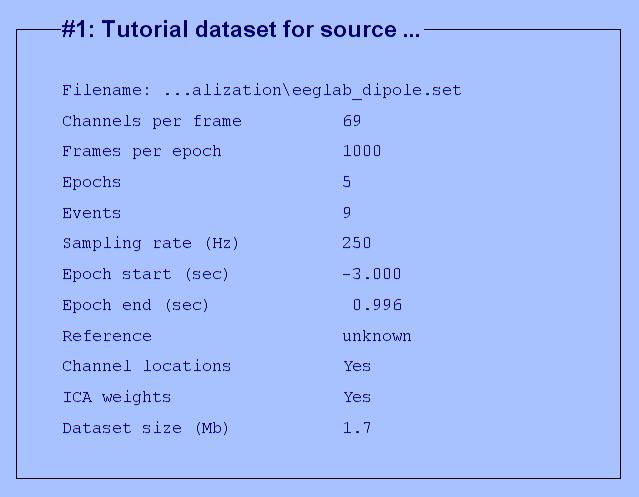

eeglab redraw

**Note that the ICA decomposition must have been run beforehand, and the channel locations must be available. Please refer to the pre-processing (*****Preprocessing.mlx***** and *****Preprocessing.html*****). **

Construct the head model. Here the **template boundary element model (BEM) from the Montreal Neurological Institute (MNI) is used. **A custom head model may be used: see the next sections of this document.

EEG = pop_dipfit_settings( EEG, 'hdmfile','C:\\Users\\mathi\\OneDrive\\Documents\\Job\\GitHub\\MATLAB\\Archives\\eeglab2021.1\\plugins\\dipfit\\standard_BEM\\standard_vol.mat',...
    'coordformat','MNI','mrifile','C:\\Users\\mathi\\OneDrive\\Documents\\Job\\GitHub\\MATLAB\\Archives\\eeglab2021.1\\plugins\\dipfit\\standard_BEM\\standard_mri.mat',...
    'chanfile','C:\\Users\\mathi\\OneDrive\\Documents\\Job\\GitHub\\MATLAB\\Archives\\eeglab2021.1\\plugins\\dipfit\\standard_BEM\\elec\\standard_1005.elc',...
    'coord_transform',[0 0 0 0 0 -1.5708 1 1 1] ,'chansel',[1:69]);
[ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Create equivalent dipole models: 

- Apply grid scanning: scann all possible positions (in the x*y*z model) to find a starting point to fit equivalent dipoles to every component. At this step some components may be assigned to a sipole of same coordinates.

- Apply non-linear interactive fitting: find the best positions for every equivalent dipole.

- Scan for the best-fitting dipole locations

% The first input are the component to scann. The second to fourth inputs
% are respectuvely the "grid in X-direction", "grid in Y-direction", and
% "grid in Z-direction". The size and spacing of the coarse grid can be
% specified (here, linspace(-85,85,24): 24 steps equally spaced between
% -radius and +radius of the sphere that best matches the electrode positions).
% The last input is a rejection threshold: maximum residual variance
% accepted. components that do not resemble a dipolar field distribution
% will not be assigned a dipole location (here, threshold: 40%).

EEG_coarse_scan = pop_dipfit_gridsearch(EEG, [1:71] ,...
    [-85     -77.6087     -70.2174     -62.8261     -55.4348     -48.0435 ...
    -40.6522     -33.2609     -25.8696     -18.4783      -11.087     -3.69565    ...
    3.69565       11.087      18.4783      25.8696      33.2609      40.6522...
    48.0435      55.4348      62.8261      70.2174      77.6087           85] ,...
    [-85     -77.6087     -70.2174     -62.8261     -55.4348     -48.0435     ...
    -40.6522     -33.2609     -25.8696     -18.4783      -11.087     -3.69565  ...
    3.69565       11.087      18.4783      25.8696      33.2609      40.6522  ...
    48.0435      55.4348      62.8261      70.2174      77.6087           85] ,...
    [0      7.72727      15.4545      23.1818      30.9091      38.6364    ...
    46.3636      54.0909      61.8182      69.5455      77.2727           85] ,0.4);

Transforming electrode coordinates to match head model
Recomputing ICA activations
the input is component data with 71 components and 69 original channels
the input is raw data with 71 channels and 5 trials


reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 71 topographies


computing the leadfields for the gridsearch on the fly
creating sourcemodel based on user specified 3D grid
using electrodes specified in the configuration
2900 dipoles inside, 4012 dipoles outside brain
making tight grid
2900 dipoles inside, 2380 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 1 seconds
scanning grid
scanning grid location 2900/2900

found minimum after scanning for topography 1 on grid point [-40.6522 -55.4348 0]
found minimum after scanning for topography 2 on grid point [-3.69565 55.4348 0]
found minimum after scanning for topography 3 on grid point [3.69565 -70.2174 15.4545]
found minimum after scanning for topography 4 on grid point [-48.0435 -3.69565 0]
found minimum after scanning for topography 5 on grid point [-48.0435 -85 0]
found minimum after scanning for topography 6 on grid point [11.087 -40.6522 46.3636]
found minimum after scanning for topography 7 on grid point [40.6522 -18.4783 0]
found minimum after scanning for topography 8 on grid 

% [ALLEEG, EEG, CURRENTSET] = eeg_store(ALLEEG, EEG, CURRENTSET);

Plotting...


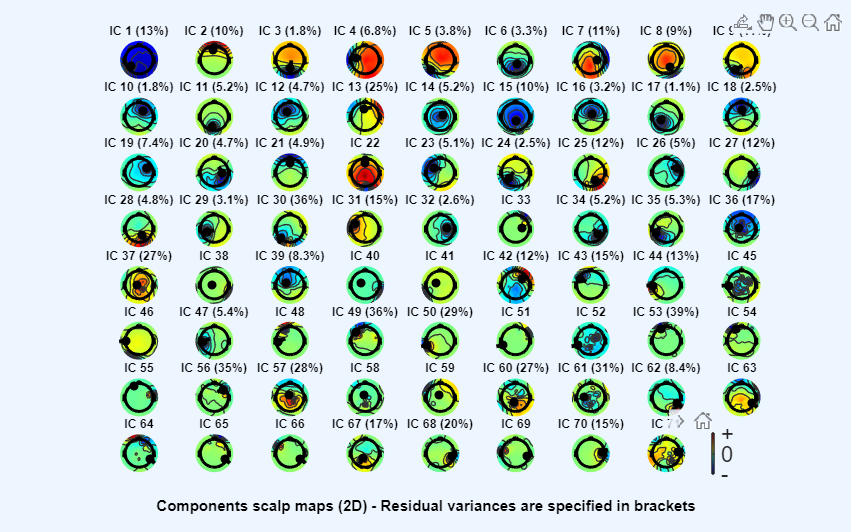

% plot
pop_topoplot(EEG_coarse_scan, 0, [1:71] ,'Components scalp maps (2D) - Residual variances are specified in brackets',...
    [8 9] ,1,'electrodes','off');

2. Apply non-linear interactive fitting: find the best positions for every equivalent dipole.

Here, an automated fitting is applied (and includes coarse fitting, so the previous step may be ignored). The algorithm uses non-linear optimization to find the exact dipole location. 

Scanning dipolar grid to find acceptable starting positions...
Transforming electrode coordinates to match head model
Recomputing ICA activations
the input is component data with 71 components and 69 original channels
the input is raw data with 71 channels and 5 trials


reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 71 topographies


computing the leadfields for the gridsearch on the fly
creating sourcemodel based on user specified 3D grid
using electrodes specified in the configuration
2900 dipoles inside, 4012 dipoles outside brain
making tight grid
2900 dipoles inside, 2380 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds
scanning grid
scanning grid location 2900/2900

found minimum after scanning for topography 1 on grid point [-40.6522 -55.4348 0]
found minimum after scanning for topography 2 on grid point [-3.69565 55.4348 0]
found minimum after scanning for topography 3 on grid point [3.69565 -70.2174 15.4545]
found minimum after scanning for topography 4 on grid point [-48.0435 -3.69565 0]
found minimum after scanning for topography 5 on grid point [-48.0435 -85 0]
found minimum after scanning for topography 6 on grid point [11.087 -40.6522 46.3636]
found minimum after scanning for topography 7 on grid point [40.6522 -18.4783 0]
found minimum after scanning for topography 8 on grid 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.133217                       0.00292
     1          24        0.0815365           7381        0.00185  
     2          32        0.0426433       0.285696        0.00108  
     3          60        0.0403563        1.00325       0.000483  
     4          76        0.0403531      0.0021829        0.00295  
     5          92        0.0401739     0.00113435        0.00576  
     6         100        0.0400685            0.1        0.00974  
     7         104        0.0400278              1        0.00639  
     8         108        0.0399657              1        0.00394  
     9         112        0.0397598              1        0.00433  
    10         124        0.0392396       0.410977        0.00293  
    11         136        0.0360621       0.987431        0.00044  
    12         148        0.0360618      0.019091

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.101541                       0.00224
     1          20        0.0972285            820        0.00205  
     2          28        0.0797225            0.5        0.00103  
     3          36        0.0752041            0.5       0.000508  
     4          52        0.0739781       0.166249        0.00106  
     5          64        0.0738222           0.05        0.00251  
     6          72        0.0725704            0.5        0.00663  
     7          84        0.0720888           0.05        0.00731  
     8          92         0.071962            0.1        0.00355  
     9         100        0.0717433            0.5        0.00281  
    10         108        0.0717051            0.1        0.00717  
    11         112        0.0716374              1        0.00744  
    12         116        0.0715395              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0175974                      0.000575
     1          20        0.0172335            820       0.000448  
     2          24        0.0164462              1       8.57e-05  
     3          28        0.0164101              1       5.82e-05  
     4          32        0.0163808              1       2.29e-05  
     5          36        0.0163771              1        1.2e-05  
     6          40        0.0163766              1       2.29e-06  
     7          44        0.0163766              1       7.13e-07  
     8          48        0.0163766              1       8.35e-08  
     9          52        0.0163766              1       4.92e-09  
    10          56        0.0163766              1       7.45e-10  

Local minimum found.

Optimizati

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0678991                       0.00241
     1          24        0.0373439           7381        0.00107  
     2          28        0.0308493              1       0.000524  
     3          32        0.0288887              1       0.000104  
     4          36        0.0288321              1       6.69e-05  
     5          40        0.0288005              1       4.23e-05  
     6          60        0.0270363       0.851395        0.00191  
     7          80        0.0270353    0.000159216        0.00196  
     8          84        0.0267474              1        0.00163  
     9          92        0.0265544            0.1        0.00105  
    10         100        0.0264773       0.430212       0.000502  
    11         104        0.0264628              1       0.000305  
    12         108        0.0264579              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0383453                        0.0984
     1           8        0.0342333              1         0.0193  
     2          12        0.0340572              1         0.0022  
     3          16        0.0340528              1        0.00216  
     4          20        0.0339923              1        0.00627  
     5          32        0.0333662        2.47197         0.0106  
     6          40        0.0333577        0.15255         0.0145  
     7          44        0.0332903              1          0.013  
     8          48        0.0329587              1         0.0165  
     9          52        0.0326535              1        0.00223  
    10          60        0.0324975       0.352454         0.0125  
    11          64        0.0323505              1         0.0116  
    12          68        0.0320363              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0333736                      0.000364
     1          24        0.0324429           7381       0.000121  
     2          28        0.0323603              1       6.67e-06  
     3          32          0.03236              1       8.09e-07  
     4          36          0.03236              1       6.23e-09  
     5          40          0.03236              1       5.12e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.108839                       0.00152
     1          24        0.0938255           7381       0.000888  
     2          32        0.0867283       0.680065       0.000224  
     3          36        0.0862295              1       0.000366  
     4          48        0.0823211            1.1        0.00313  
     5          64        0.0495513      0.0817933       0.000854  
     6         120         0.035256       0.700504       6.51e-05  
     7         136        0.0352559          0.001       5.59e-05  
     8         168         0.034298        100.164       0.000395  
     9         184         0.034298     0.00211688       0.000385  
    10         200        0.0333551        59.0349       0.000439  
    11         212        0.0333021      0.0581502       0.000689  
    12         220        0.0330745             1

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0901778                        0.0017
     1          24        0.0763705           7381       0.000575  
     2          28        0.0746421              1       0.000428  
     3          32        0.0740793              1       4.56e-05  
     4          36        0.0740628              1        8.3e-06  
     5          40        0.0740625              1       4.01e-07  
     6          44        0.0740625              1       5.31e-08  
     7          48        0.0740625              1       1.82e-09  
     8          56        0.0740625       0.456918        8.8e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          0.10867                       0.00267
     1          20         0.103432            820        0.00201  
     2          28        0.0972792            0.5       0.000667  
     3          36        0.0957582            0.5       0.000783  
     4          44        0.0951589            0.1       0.000817  
     5          52        0.0941367            0.1       0.000741  
     6          60         0.093522            0.1       0.000636  
     7          72        0.0933477       0.222976       0.000483  
     8          76        0.0933103              1        0.00116  
     9          84        0.0932867       0.236284       0.000197  
    10          88         0.093274              1       0.000299  
    11          92        0.0932692              1       8.61e-05  
    12          96        0.0932691              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0182795                      0.000628
     1          20        0.0179023            820       0.000493  
     2          24        0.0172485              1       4.27e-05  
     3          28        0.0172418              1       1.64e-05  
     4          32        0.0172404              1       5.73e-06  
     5          36        0.0172402              1       1.31e-06  
     6          40        0.0172402              1       9.61e-08  
     7          44        0.0172402              1       7.06e-09  
     8          48        0.0172402              1       1.38e-09  
     9          52        0.0172402              1        1.7e-10  

Local minimum found.

Optimization completed because the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0522176                       0.00248
     1          20        0.0477406            820        0.00162  
     2          24        0.0440971              1        0.00208  
     3          36        0.0386833       0.150835        0.00168  
     4          48        0.0381368       0.244418        0.00177  
     5          56        0.0372916       0.244157        0.00123  
     6          60        0.0371643              1        0.00156  
     7          64        0.0367725              1       0.000695  
     8          68        0.0366852              1       0.000998  
     9          72        0.0366148              1       0.000163  
    10          76        0.0366016              1       6.76e-05  
    11          80        0.0365986              1       7.83e-06  
    12          84        0.0365986              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0473981                      0.000565
     1          20        0.0470629            820       0.000499  
     2          24        0.0457017              1       5.34e-05  
     3          28        0.0456899              1       8.89e-06  
     4          32        0.0456896              1       1.93e-06  
     5          36        0.0456896              1       2.43e-07  
     6          40        0.0456896              1       3.78e-09  
     7          44        0.0456896              1       9.35e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.252666                        0.0041
     1          24         0.153317           7381         0.0025  
     2          36         0.148378      0.0715812       0.000438  
     3          48         0.147235        3.47179       0.000619  
     4          52         0.146758              1       0.000537  
     5          60         0.145922       0.413672       0.000405  
     6          64         0.145407              1       0.000592  
     7          76         0.144623           0.19       0.000924  
     8          84         0.144191            0.1        0.00103  
     9          88         0.143284              1       0.000489  
    10          92         0.143173              1       0.000237  
    11          96         0.143086              1       8.89e-05  
    12         100         0.143077              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0519339                      0.000567
     1          20        0.0515077            820       0.000497  
     2          24        0.0501007              1       2.76e-05  
     3          28         0.050097              1       8.53e-06  
     4          32        0.0500966              1       4.82e-07  
     5          36        0.0500966              1       2.88e-08  
     6          40        0.0500966              1       2.47e-09  
     7          52        0.0500966       0.070555       9.78e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.103949                      0.000279
     1          24         0.103558           7381       6.19e-05  
     2          28         0.103528              1       2.48e-05  
     3          32         0.103522              1       6.45e-06  
     4          36         0.103522              1       9.72e-07  
     5          40         0.103522              1       3.94e-08  
     6          44         0.103522              1       1.85e-09  
     7          48         0.103522              1       1.86e-09  
     8          56         0.103522       0.394032       4.12e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0316541                      0.000408
     1          20        0.0313225            820       0.000368  
     2          24        0.0304304              1       7.83e-05  
     3          28        0.0304155              1       2.83e-05  
     4          32        0.0304139              1       6.75e-06  
     5          36        0.0304138              1       3.84e-07  
     6          40        0.0304138              1       2.89e-08  
     7          44        0.0304138              1       1.82e-09  
     8          48        0.0304138              1       7.92e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.011268                      0.000521
     1          20        0.0109709            820       0.000451  
     2          24       0.00972295              1       2.18e-05  
     3          28       0.00972057              1       5.38e-06  
     4          32       0.00972042              1       1.27e-07  
     5          36       0.00972042              1       4.46e-09  
     6          40       0.00972042              1       3.33e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<<a href = "matlab

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0248332                      0.000397
     1          20        0.0246308            820       0.000348  
     2          24        0.0240304              1       1.95e-05  
     3          28        0.0240277              1       7.01e-06  
     4          32        0.0240274              1       1.05e-06  
     5          36        0.0240274              1       9.53e-08  
     6          40        0.0240274              1       6.59e-09  
     7          44        0.0240274              1       1.16e-09  
     8          56        0.0240274      0.0684778       5.46e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0736764                      0.000763
     1          20        0.0731378            820       0.000541  
     2          24        0.0725465              1       5.09e-05  
     3          28        0.0725432              1        7.4e-06  
     4          32        0.0725431              1        2.4e-07  
     5          36        0.0725431              1       1.13e-08  
     6          40        0.0725431              1       4.57e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<<a href = "matlab

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0474348                      0.000541
     1          20        0.0470527            820       0.000444  
     2          24        0.0462042              1       4.98e-05  
     3          28        0.0461926              1       2.75e-05  
     4          32        0.0461887              1       5.34e-06  
     5          36        0.0461885              1       1.28e-06  
     6          40        0.0461885              1       7.18e-08  
     7          44        0.0461885              1       4.25e-09  
     8          48        0.0461885              1       2.25e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0494295                       0.00137
     1          20        0.0470628            820        0.00128  
     2          24        0.0373869              1       0.000632  
     3          28        0.0362695              1       0.000527  
     4          32         0.035371              1       9.05e-05  
     5          36        0.0353514              1       3.03e-05  
     6          40        0.0353497              1       2.98e-06  
     7          44        0.0353497              1       1.21e-07  
     8          48        0.0353497              1       3.68e-08  
     9          52        0.0353497              1       4.88e-09  
    10          56        0.0353497              1       6.98e-10  

Local minimum found.

Optimizati

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.427123                      0.000231
     1          24         0.426588           7381       0.000135  
     2          28         0.426354              1       1.02e-05  
     3          32         0.426353              1       3.28e-06  
     4          36         0.426353              1       2.71e-07  
     5          40         0.426353              1       3.36e-08  
     6          44         0.426353              1       3.73e-09  
     7          52         0.426353       0.326156       1.49e-09  

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the current search direction.

<

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4           0.0514                      0.000408
     1          20         0.051118            820       0.000347  
     2          24        0.0504485              1       5.68e-05  
     3          28        0.0504338              1       3.32e-05  
     4          32        0.0504258              1       6.44e-06  
     5          36        0.0504256              1       1.34e-06  
     6          40        0.0504256              1        1.8e-08  
     7          44        0.0504256              1       3.77e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0246682                      0.000276
     1          20        0.0245899            820       0.000236  
     2          24        0.0243768              1        6.2e-06  
     3          28        0.0243767              1       9.65e-07  
     4          32        0.0243766              1       4.76e-07  
     5          36        0.0243766              1       8.91e-08  
     6          40        0.0243766              1       1.44e-08  
     7          44        0.0243766              1       8.11e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.115313                       0.00215
     1          24        0.0895636           7381        0.00113  
     2          28        0.0863827              1        0.00112  
     3          32         0.078303              1       0.000328  
     4          36        0.0775808              1       0.000174  
     5          40        0.0773789              1       5.04e-05  
     6          44        0.0773658              1       8.84e-06  
     7          48        0.0773656              1        2.4e-06  
     8          52        0.0773655              1       2.31e-07  
     9          56        0.0773655              1       1.71e-08  
    10          60        0.0773655              1       3.17e-09  
    11          64        0.0773655              1       4.84e-10  



reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0497956                      0.000897
     1          20        0.0486256            820       0.000601  
     2          28        0.0480842       0.429545        0.00026  
     3          36        0.0480679       0.310294       0.000167  
     4          40        0.0480459              1       0.000128  
     5          44        0.0480266              1       0.000103  
     6          48        0.0480236              1       2.55e-05  
     7          52        0.0480229              1       1.75e-05  
     8          56        0.0480228              1       3.55e-06  
     9          60        0.0480228              1       1.42e-07  
    10          64        0.0480228              1       1.16e-08  
    11          68        0.0480228              1       1.49e-09  



reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.120096                       0.00226
     1          24        0.0847623           7381         0.0021  
     2          40        0.0586422        0.14271        0.00337  
     3          52        0.0577349      0.0621825        0.00371  
     4          60        0.0552714            0.1        0.00319  
     5          68         0.050737       0.480364        0.00642  
     6          80        0.0500154      0.0429748        0.00305  
     7          88        0.0499696       0.298342       0.000631  
     8          92        0.0499326              1       0.000656  
     9          96        0.0498838              1        0.00105  
    10         100        0.0498693              1       0.000312  
    11         104        0.0498652              1       2.39e-05  
    12         108        0.0498651              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0476341                      0.000183
     1          20        0.0476017            820       0.000152  
     2          24        0.0475177              1       2.01e-05  
     3          28        0.0475156              1       1.49e-05  
     4          32        0.0475138              1       4.42e-06  
     5          36        0.0475137              1       2.47e-06  
     6          40        0.0475137              1       2.12e-07  
     7          44        0.0475137              1       2.54e-08  
     8          48        0.0475137              1       5.87e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0308479                      0.000779
     1          20         0.029888            820       0.000627  
     2          24        0.0276262              1       0.000104  
     3          28        0.0275858              1       1.44e-05  
     4          32        0.0275854              1       2.06e-06  
     5          36        0.0275854              1       3.61e-07  
     6          40        0.0275854              1       7.58e-09  
     7          44        0.0275854              1       3.69e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.363298                        0.0939
     1           8         0.355316              1         0.0127  
     2          12         0.355152              1        0.00743  
     3          16         0.354956              1         0.0101  
     4          20         0.354542              1         0.0147  
     5          24         0.354066              1         0.0222  
     6          28         0.353183              1         0.0278  
     7          32         0.351576              1         0.0195  
     8          36         0.350435              1        0.00464  
     9          44         0.350079       0.351587         0.0191  
    10          48         0.349593              1          0.013  
    11          52         0.349274              1        0.00232  
    12          60         0.349154       0.42401

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.152783                       0.00299
     1          24         0.146764          455.5        0.00712  
     2          56         0.127022       0.365704        0.00735  
     3          76         0.127017     0.00030175        0.00881  
     4          84         0.124306        2.54286          0.059  
     5          88         0.122688              1         0.0527  
     6          92          0.12082              1         0.0442  
     7         108        0.0985107        2.84741        0.00474  
     8         112        0.0980138              1         0.0016  
     9         120        0.0975006       0.478869        0.00602  
    10         124        0.0972366              1       0.000536  
    11         128        0.0971753              1       0.000449  
    12         132         0.097117              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0257793                      0.000381
     1          20        0.0256695            820        0.00023  
     2          24        0.0256004              1       2.28e-05  
     3          28        0.0255985              1       1.56e-05  
     4          32        0.0255967              1       6.06e-06  
     5          36        0.0255966              1       4.64e-06  
     6          40        0.0255964              1       5.42e-07  
     7          44        0.0255964              1       5.55e-08  
     8          48        0.0255964              1       8.05e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.458326                        0.0771
     1          16         0.399355            5.5         0.0467  
     2          24         0.396306            0.1         0.0356  
     3          28         0.391132              1         0.0166  
     4          32         0.386024              1          0.103  
     5          36         0.378717              1         0.0556  
     6          40         0.368706              1         0.0156  
     7          56         0.324191        1.69659         0.0432  
     8          76         0.300564        1.02084         0.0182  
     9          84         0.300541        0.13154         0.0149  
    10          92         0.298199       0.423065         0.0489  
    11          96         0.294945              1         0.0205  
    12         104         0.292059       0.11493

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0516676                      0.000899
     1          20        0.0509031            820       0.000678  
     2          24        0.0498742              1       0.000204  
     3          28        0.0498099              1       4.69e-05  
     4          32        0.0498022              1       9.99e-06  
     5          36        0.0498018              1       6.61e-07  
     6          40        0.0498018              1       2.68e-08  
     7          44        0.0498018              1       1.15e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0534839                       0.00052
     1          20        0.0532465            820       0.000371  
     2          24        0.0529642              1       3.05e-05  
     3          28        0.0529605              1       5.49e-06  
     4          32        0.0529603              1       1.62e-06  
     5          36        0.0529603              1       4.27e-07  
     6          40        0.0529603              1       3.59e-08  
     7          44        0.0529603              1       1.42e-09  
     8          48        0.0529603              1       4.15e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.167046                      0.000272
     1          20         0.166923            820       0.000234  
     2          24         0.166534              1       7.72e-06  
     3          28         0.166533              1       1.93e-06  
     4          32         0.166533              1       5.04e-07  
     5          36         0.166533              1       3.47e-07  
     6          40         0.166533              1       2.02e-08  
     7          44         0.166533              1       5.01e-09  
     8          48         0.166533              1       3.24e-09  
     9          52         0.166533              1       2.45e-09  
    10          56         0.166533              1       2.21e-09  

Local minimum possible.

fminunc stop

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.272419                      0.000317
     1          24         0.271808           7381       8.13e-05  
     2          28         0.271746              1        1.2e-05  
     3          32         0.271744              1       4.58e-06  
     4          36         0.271744              1       4.92e-07  
     5          40         0.271744              1       1.22e-07  
     6          44         0.271744              1       2.98e-09  
     7          48         0.271744              1       2.61e-09  
     8          60         0.271744      0.0305539       3.35e-09  
     9          64         0.271744              1       1.86e-09  

Local minimum possible.

fminunc stopped because the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.773231                       0.00505
     1          16         0.770713             91        0.00491  
     2          20         0.765846              1         0.0244  
     3          28         0.764731        0.18934         0.0147  
     4          52         0.711365        1.67567        0.00807  
     5          56          0.71026              1         0.0195  
     6          68          0.67868       0.896296         0.0164  
     7          80         0.675426      0.0197073         0.0135  
     8          88         0.670214        0.65697        0.00561  
     9          92          0.66823              1        0.00662  
    10         100         0.667199            0.1         0.0103  
    11         104         0.665819              1         0.0118  
    12         108          0.66285              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.083164                      0.000492
     1          20        0.0828731            820       0.000395  
     2          24        0.0818948              1       6.48e-05  
     3          28        0.0818716              1       2.68e-05  
     4          32        0.0818676              1       7.69e-07  
     5          36        0.0818676              1       1.33e-08  
     6          40        0.0818676              1       2.24e-09  
     7          48        0.0818676       0.255207       6.11e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.879613                       0.00423
     1          20         0.871802        514.717        0.00763  
     2          28         0.868116        0.31578        0.00177  
     3          44         0.852462        2.25294        0.00761  
     4          48         0.851759              1        0.00798  
     5          52         0.851376              1        0.00714  
     6          56         0.848268              1         0.0013  
     7          60         0.848168              1        0.00157  
     8          64         0.848098              1        0.00155  
     9          68           0.8475              1        0.00172  
    10          92         0.845078        0.40951        0.00437  
    11          96         0.844675              1        0.00485  
    12         100         0.840051              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          0.62294                       0.00484
     1          56         0.380016        4590.78        0.00188  
     2          64         0.378436            0.1        0.00527  
     3          84         0.377707    0.000372801        0.00345  
     4          96         0.376922           0.01         0.0108  
     5         100         0.376067              1         0.0117  
     6         108         0.375881       0.243547       0.000999  
     7         112         0.375825              1       0.000316  
     8         116         0.375778              1        0.00276  
     9         120         0.375767              1        9.6e-05  
    10         124         0.375765              1       6.19e-05  
    11         128         0.375765              1       2.19e-06  
    12         132         0.375765              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.122666                      0.000356
     1          20         0.122557            820       0.000313  
     2          24          0.12218              1       7.55e-05  
     3          28         0.122154              1       5.35e-05  
     4          32         0.122132              1       5.93e-06  
     5          36         0.122132              1        1.3e-06  
     6          40         0.122132              1       1.11e-07  
     7          44         0.122132              1       8.36e-09  
     8          48         0.122132              1       1.02e-09  
     9          52         0.122132              1       4.56e-10  

Local minimum found.

Optimization completed because the 

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.149927                       0.00394
     1          16         0.148192             91        0.00491  
     2          24         0.145091            0.1        0.00361  
     3          32          0.14361       0.385104         0.0165  
     4          36         0.143307              1        0.00227  
     5          40         0.143034              1        0.00157  
     6          48         0.142899        0.64447        0.00301  
     7          52         0.142848              1        0.00165  
     8          56         0.142757              1        0.00141  
     9          60         0.142713              1        0.00196  
    10          64         0.142615              1        0.00395  
    11          72         0.142513        0.71699        0.00154  
    12          76         0.142293              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          0.13284                         0.056
     1          24        0.0754867         14.106         0.0455  
     2          36        0.0734423      0.0126255         0.0164  
     3          40        0.0721533              1        0.00984  
     4          44        0.0704014              1         0.0433  
     5          48        0.0686124              1         0.0355  
     6          52        0.0663231              1         0.0043  
     7          60        0.0650723       0.433636         0.0384  
     8          64        0.0637381              1         0.0265  
     9          68        0.0614037              1         0.0558  
    10          76        0.0568651            0.5          0.013  
    11          88          0.05634      0.0100083        0.00253  
    12          96        0.0559791            0.

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.488252                       0.00183
     1          32         0.482246        1033.24       0.000491  
     2          40         0.482175       0.425513       0.000757  
     3          48         0.481865       0.472118       0.000562  
     4          52          0.48184              1       0.000275  
     5          56         0.481821              1       0.000286  
     6          60         0.481802              1         0.0002  
     7          64         0.481796              1       5.02e-05  
     8          72         0.481791       0.337413       0.000346  
     9          76         0.481787              1       1.72e-05  
    10          80         0.481786              1       4.78e-05  
    11          84         0.481786              1       4.04e-05  
    12          88         0.481786              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.514056                        0.0125
     1          40         0.316641        914.914         0.0504  
     2          44         0.285092              1         0.0319  
     3          60         0.192991          0.271        0.00872  
     4          76         0.192001     0.00218664         0.0381  
     5          80         0.188399              1         0.0281  
     6          88           0.1658       0.367641         0.0102  
     7          96         0.163508            0.1        0.00725  
     8         104         0.161822       0.105551         0.0121  
     9         112         0.157587        0.33347         0.0369  
    10         120         0.147332       0.637142         0.0588  
    11         128         0.143982       0.661363         0.0682  
    12         132         0.140167              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0535899                       0.00077
     1          20        0.0531573            820       0.000517  
     2          24        0.0525394              1       0.000165  
     3          28        0.0524651              1       7.22e-05  
     4          32        0.0524591              1       2.74e-05  
     5          36        0.0524579              1       1.82e-05  
     6          40        0.0524565              1       1.44e-05  
     7          44        0.0524563              1       4.56e-06  
     8          48        0.0524563              1       4.21e-07  
     9          52        0.0524563              1       2.69e-08  
    10          56        0.0524563              1        1.8e-09  
    11          60        0.0524563              1       3.31e-10  



reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.595698                         0.039
     1          36         0.457823        35.6006        0.00905  
     2          44         0.456694       0.314677           0.03  
     3          48         0.433436              1          0.132  
     4          60          0.39025      0.0181654         0.0179  
     5          76         0.389316     0.00237221        0.00779  
     6          80         0.389261              1         0.0085  
     7          84         0.38903

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.357383                        0.0292
     1          12          0.34887             10         0.0102  
     2          16         0.347303              1         0.0147  
     3          20         0.345692              1        0.00771  
     4          24          0.33708              1         0.0194  
     5          36         0.329688      0.0835769         0.0364  
     6          44         0.324173       0.474043          0.041  
     7          48          0.31214              1         0.0202  
     8          52          0.30967              1         0.0154  
     9          60         0.307645       0.241395          0.008  
    10          68         0.307248       0.315303         0.0129  
    11          72         0.306641              1          0.011  
    12          76          0.30447              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.286931                         0.544
     1          12         0.258841       0.287123           0.11  
     2          16         0.256652              1         0.0557  
     3          20         0.255997              1          0.024  
     4          24         0.255845              1         0.0206  
     5          28         0.255172              1         0.0272  
     6          32         0.253476              1         0.0692  
     7          36         0.250523              1          0.118  
     8          40         0.247214              1          0.148  
     9          44         0.241046              1          0.161  
    10          48         0.224803              1          0.112  
    11          56          0.21767       0.182328         0.0566  
    12          72          0.20564       0.99084

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.735488                        0.0152
     1          44         0.666516        143.056         0.0134  
     2          60         0.665949          0.005         0.0124  
     3          84         0.589372        13.0983         0.0373  
     4          96         0.588854      0.0102331          0.026  
     5         100         0.585689              1         0.0207  
     6         120         0.550065         1.2611         0.0264  
     7         136         0.53976

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.446381                        0.0135
     1          12         0.443729             10        0.00563  
     2          16         0.442498              1         0.0105  
     3          24         0.416167             10         0.0139  
     4          36         0.413747      0.0103816        0.00777  
     5          40         0.398209              1         0.0142  
     6          48         0.398046            0.1        0.00636  
     7          56         0.396833             10         0.0116  
     8          60         0.396396              1        0.00661  
     9          64         0.396359              1        0.00315  
    10          68         0.396298              1       0.000874  
    11          72         0.396284              1        0.00117  
    12          76         0.396278              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.387482                        0.0437
     1           8         0.385163              1         0.0216  
     2          12         0.383056              1         0.0178  
     3          20         0.375174             10          0.101  
     4          24         0.365706              1         0.0737  
     5          28         0.356361              1        0.00882  
     6          36         0.353169       0.495362         0.0303  
     7          40         0.351767              1         0.0186  
     8          44         0.350886              1        0.00345  
     9          48         0.350772              1        0.00533  
    10          52          0.35074              1        0.00135  
    11          56         0.350737              1       0.000186  
    12          64         0.350736             1

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.521281                        0.0362
     1           8         0.518971              1         0.0244  
     2          12         0.516375              1         0.0364  
     3          16         0.514878              1         0.0128  
     4          20         0.512189              1         0.0118  
     5          24         0.497127              1         0.0178  
     6          32         0.496442       0.352239         0.0328  
     7          36         0.495051              1         0.0238  
     8          40         0.492153              1         0.0164  
     9          44         0.490402              1        0.00492  
    10          52          0.48348       0.792912         0.0262  
    11          64         0.483264           0.01         0.0354  
    12          68         0.481741              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.686049                        0.0133
     1          28         0.651945        185.861         0.0103  
     2          48         0.544957        1.30302         0.0252  
     3          56         0.463107       0.765642         0.0571  
     4          76         0.450943     0.00239955         0.0712  
     5          80          0.35908              1          0.104  
     6          88         0.346313       0.106096          0.137  
     7         100         0.299271      0.0916682         0.0177  
     8         104          0.29905              1         0.0132  
     9         108         0.298725              1        0.00148  
    10         116         0.298524             10        0.00418  
    11         128         0.298463       0.047604        0.00788  
    12         132         0.298372              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          0.34729                         0.112
     1          16         0.278831        2.65712         0.0204  
     2          24         0.278479        0.29104         0.0153  
     3          32         0.271722             10         0.0144  
     4          40         0.264986            0.1        0.00712  
     5          48         0.261756            0.1         0.0413  
     6          52         0.260435              1         0.0293  
     7          56         0.257342              1         0.0932  
     8          60         0.251839              1         0.0191  
     9          64         0.247606              1        0.00631  
    10          72         0.241956       0.460704          0.137  
    11          88          0.23344      0.0318827        0.00257  
    12          96          0.23337            0.

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.275904                      0.000163
     1          24         0.275649           7381       8.65e-05  
     2          28         0.275561              1       3.94e-05  
     3          32         0.275545              1       6.46e-06  
     4          36         0.275544              1        1.5e-06  
     5          40         0.275544              1       3.91e-07  
     6          44         0.275544              1       2.18e-07  
     7          48         0.275544              1       3.65e-08  
     8          52         0.275544              1       6.33e-09  
     9          60         0.275544       0.346435       4.47e-09  
    10          76         0.275544     0.00441857       9.26e-10  

Local minimum found.

Optimizati

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.743996                        0.0112
     1          44         0.463246        248.223         0.0111  
     2          56         0.463123           0.01         0.0285  
     3          72         0.440708          0.271        0.00969  
     4          84         0.429251      0.0683034         0.0428  
     5          92         0.422454       0.168373         0.0136  
     6         100         0.419441        0.43441            0.1  
     7         104         0.416219              1          0.226  
     8         116         0.415179           0.01          0.166  
     9         128         0.414559      0.0612042         0.0397  
    10         144         0.411855         28.848         0.0681  
    11         148          0.41173              1         0.0662  
    12         152         0.411303              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.483682                       0.00404
     1          24         0.422952           7381        0.00196  
     2          36         0.393598       0.881664        0.00212  
     3          48         0.393507           0.01        0.00403  
     4          60          0.39312      0.0372248       0.000735  
     5          68         0.393045            0.1         0.0015  
     6          72         0.393028              1       0.000347  
     7          76         0.393024              1       0.000172  
     8          80         0.393024              1       1.62e-05  
     9          84         0.393024              1       1.94e-05  
    10          88         0.393024              1       1.01e-07  
    11          92         0.393024              1       1.89e-09  



reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.269174                      0.000291
     1          20         0.269084            820       0.000261  
     2          24         0.268742              1       5.32e-05  
     3          28         0.268713              1       5.65e-05  
     4          32         0.268671              1       1.53e-05  
     5          36         0.268669              1       3.21e-06  
     6          40         0.268669              1       9.76e-08  
     7          44         0.268669              1       3.75e-09  
     8          48         0.268669              1        7.5e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the val

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.305053                       0.00155
     1          32          0.29941        1034.92        0.00388  
     2          48         0.299069     0.00528192        0.00389  
     3          52         0.298514              1        0.00621  
     4          56         0.297439              1        0.00392  
     5          64         0.296007            0.5         0.0025  
     6          68         0.295867              1        0.00114  
     7          76         0.295726            0.1        0.00166  
     8          84         0.295651            0.1        0.00191  
     9          92         0.295597       0.104762        0.00206  
    10         100         0.295515            0.1        0.00292  
    11         108         0.295333        0.21818        0.00819  
    12         112         0.295133              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0838166                       0.00621
     1          16        0.0791915             91        0.00595  
     2          24        0.0727831       0.144131        0.00556  
     3          36        0.0691489      0.0861898        0.00281  
     4          44        0.0689685       0.374473       0.000437  
     5          48        0.0689471              1       0.000298  
     6          52         0.068917              1       0.000176  
     7          56        0.0689116              1       0.000104  
     8          60        0.0688956              1       0.000372  
     9          64        0.0688861              1       0.000416  
    10          68        0.0688787              1       0.000174  
    11          72        0.0688777              1       2.14e-05  
    12          76        0.0688776              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.418325                      0.000115
     1          24         0.418141           7381       7.41e-05  
     2          28         0.418029              1       1.41e-05  
     3          32         0.418028              1       1.22e-05  
     4          36         0.418027              1       3.58e-08  
     5          40         0.418027              1       9.51e-10  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.542839                        0.0137
     1          12         0.541306        8.28092        0.00605  
     2          20         0.537882             10         0.0191  
     3          28         0.536645       0.617573          0.032  
     4          32         0.530957              1         0.0193  
     5          36         0.522095              1         0.0153  
     6          44         0.520372            0.1         0.0135  
     7          52         0.519822            0.1         0.0206  
     8          56         0.518877              1         0.0357  
     9          60         0.517817              1        0.00308  
    10          64         0.517041              1         0.0155  
    11          72         0.516785       0.599795         0.0252  
    12          76         0.516067              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.426042                          0.11
     1           8         0.403662              1          0.102  
     2          16         0.385986            0.1         0.0707  
     3          24         0.378447       0.450965        0.00617  
     4          32         0.373808             10        0.00433  
     5          40         0.370597       0.391785         0.0271  
     6          44         0.369266              1         0.0133  
     7          56         0.364631            1.9         0.0161  
     8          68         0.364341           0.01         0.0307  
     9          72         0.363352              1         0.0387  
    10          76         0.360842              1         0.0992  
    11          84         0.358775       0.269916         0.0159  
    12          88         0.357667              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.686018                        0.0135
     1          24          0.65614          184.3        0.00744  
     2          36          0.54159        1.63329         0.0103  
     3          44         0.415194       0.791196         0.0121  
     4          56         0.414558      0.0263859        0.00546  
     5          60          0.41128              1        0.00276  
     6          68         0.411115            0.5       0.000334  
     7          72         0.411103              1       0.000156  
     8          76         0.411099              1       5.33e-06  
     9          80         0.411099              1       6.72e-06  
    10          84         0.411099              1       2.11e-06  
    11          88         0.411099              1        2.1e-07  
    12          92         0.411099              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.173758                      0.000265
     1          20         0.173662            820       0.000228  
     2          24         0.173249              1       0.000128  
     3          28         0.173141              1       0.000111  
     4          32         0.173012              1       5.95e-05  
     5          36         0.172987              1       1.18e-05  
     6          40         0.172985              1       2.17e-06  
     7          44         0.172985              1       6.58e-07  
     8          48         0.172985              1       1.16e-07  
     9          52         0.172985              1       1.51e-08  
    10          56         0.172985              1       4.19e-09  
    11          64         0.172985       0.331203       1.94e-09  
    12          68         0.172985              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          0.20146                        0.0345
     1          28         0.166604        23.3793        0.00855  
     2          32         0.164515              1         0.0341  
     3          44         0.151235           0.25         0.0185  
     4          52         0.150925       0.374269         0.0225  
     5          56         0.150095              1          0.019  
     6          60         0.147896              1        0.00647  
     7          68         0.147308       0.497968        0.00596  
     8          72          0.14711              1        0.00437  
     9          76         0.146988              1        0.00165  
    10          80         0.146963              1        0.00137  
    11         108         0.145524        104.851        0.00881  
    12         120          0.14551      0.027333

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies
                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.606634                         0.244
     1           8         0.576076              1          0.195  
     2          16         0.571273       0.462546         0.0146  
     3          28         0.562565             91          0.144  
     4          32          0.55891              1         0.0968  
     5          40          0.55619            0.1          0.122  
     6          48         0.547565       0.664521          0.206  
     7          52         0.53782

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.149353                        0.0499
     1          16         0.136966        5.45525         0.0111  
     2          20         0.135264              1          0.017  
     3          24         0.125168              1         0.0471  
     4          28         0.122249              1         0.0127  
     5          32         0.120202              1         0.0281  
     6          36          0.11877              1         0.0145  
     7          40         0.117968              1         0.0108  
     8          48         0.117856       0.291479        0.00238  
     9          52          0.11772              1         0.0063  
    10          56         0.117696              1       0.000869  
    11          60         0.117688              1       0.000707  
    12          64         0.117684              

reading 'headmodel' from file 'C:\Users\mathi\OneDrive\Documents\Job\GitHub\MATLAB\Archives\eeglab2021.1\plugins\dipfit\standard_BEM\standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 69 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.704933                        0.0753
     1           8         0.692716              1         0.0663  
     2          16         0.684154       0.114709          0.043  
     3          24         0.679351       0.556369         0.0126  
     4          32         0.664891             10          0.021  
     5          40         0.662621            0.1         0.0269  
     6          44         0.654951              1          0.134  
     7          52         0.651062       0.263336         0.0622  
     8          56          0.64962              1         0.0317  
     9          60         0.648945              1         0.0338  
    10          64         0.648483              1         0.0157  
    11          68         0.648008              1        0.00558  
    12          72         0.647681              

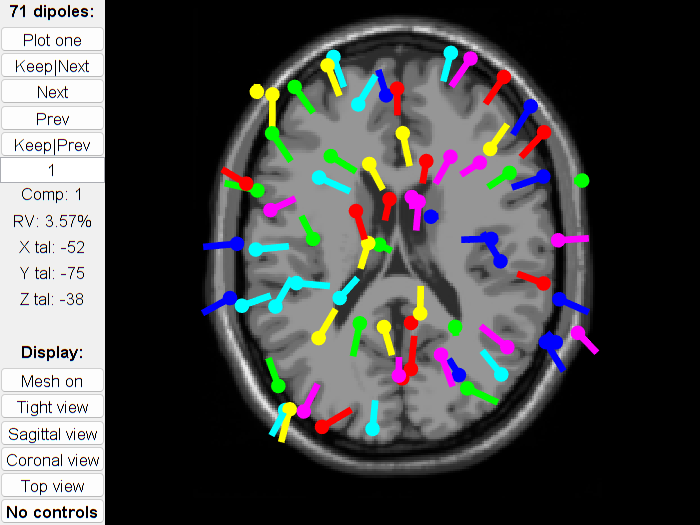

EEG = pop_multifit(EEG, [1:71],'threshold',100,'dipplot','on','plotopt',{'normlen','on'});

rmpath(PathtoEEGLab);

### Boundary Element Method (BEM)

clear; clc; close all; 
addpath(PathToFieldtrip); ft_defaults;

Here a dataset from Fieldtrip tutorials will be used. More information here: [https://www.fieldtriptoolbox.org/tutorial/meg_language/](https://www.fieldtriptoolbox.org/tutorial/meg_language/)

(Also, see all the datasets from Fieldtrip here: [https://www.fieldtriptoolbox.org/faq/datasets/)](https://www.fieldtriptoolbox.org/faq/datasets/))

mri_data = ft_read_mri('Subject01.mri');

 In ft_estimate_units at line 51
 In ft_determine_units at line 113
 In ft_read_mri at line 554



the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 1 seconds


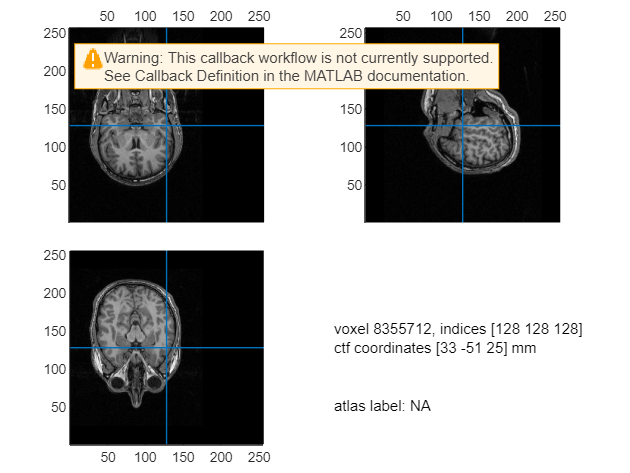

% Plot
cfg = []; cfg.method = 'ortho';
ft_sourceplot(cfg, mri_data)

Align the MRI coordinate to the EEG electrodes and source model.

The positive x-axis is pointing towards anterior
The positive y-axis is pointing towards the left
The positive z-axis is pointing towards superior
The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


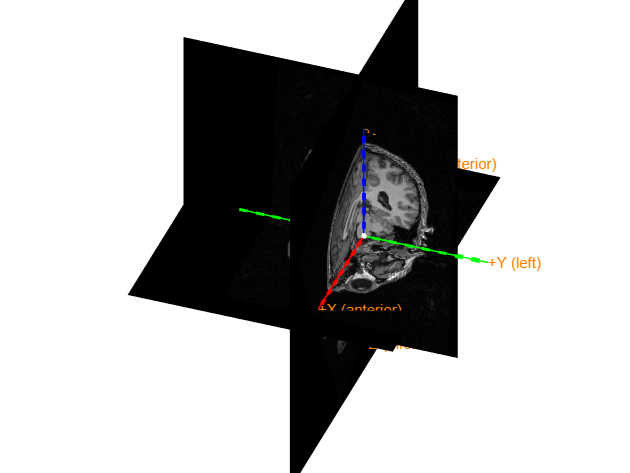

ans = struct with fields:
          dim: [256 256 256]
      anatomy: [256×256×256 int16]
          hdr: [1×1 struct]
    transform: [4×4 double]
         unit: 'mm'
     coordsys: 'ctf'


% Check the coordinate system used by the MRI data
ft_determine_coordsys(mri_data)

% Here, the CTF system is used

% Realign: the positions of the LPA, RPA and nasion must be defined.

cfg = []; cfg.method = 'fiducial';
cfg.fiducial.nas = [87 60 116];
cfg.fiducial.lpa = [29 145 155];
cfg.fiducial.rpa = [144 142 158];
cfg.coordsys = 'ctf'; % the desired coordinate system
mri_data_realigned = ft_volumerealign(cfg, mri_data);

the input is volume data with dimensions [256 256 256]
the call to "ft_volumerealign" took 0 seconds


the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 0 seconds



% Plot
cfg = []; cfg.method = 'ortho'; ft_sourceplot(cfg, mri_data_realigned);

We see that the data is plotted upside down. The MRI image can be resliced: 

cfg = []; cfg.method = 'linear';
mri_data_resliced = ft_volumereslice(cfg, mri_data_realigned);

the input is volume data with dimensions [256 256 256]
 In getdimord>warning_dimord_could_not_be_determined at line 784
 In getdimord at line 734
 In ft_volumereslice at line 167

reslicing from [256 256 256] to [256 256 256]
the input is volume data with dimensions [256 256 256]
the input is volume data with dimensions [256 256 256]
selecting subvolume of 90.4%
reslicing and interpolating anatomy
inteinterpolating 100.0
the call to "ft_sourceinterpolate" took 3 seconds
the call to "ft_volumereslice" took 3 seconds


the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 0 seconds


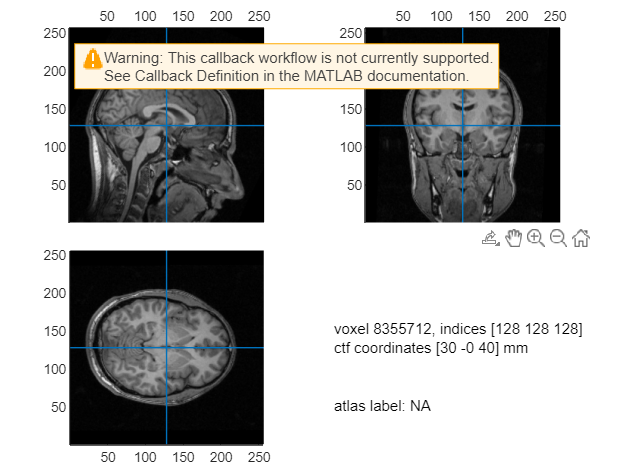

% Plot
cfg = []; cfg.method = 'ortho';
ft_sourceplot(cfg, mri_data_resliced)

For the BEM method, the data must now be segmented to differentiate the scalp, skull, and brain. Each voxel will be attributed to a structure. This step may be long to compute. It is recommended to save the data for future use.

cfg           = []; cfg.output    = {'brain', 'skull', 'scalp'};
mri_data_segmented_BEM = ft_volumesegment(cfg, mri_data_resliced);

the input is volume data with dimensions [256 256 256]
using 'OldNorm' normalisation
Smoothing by 0 & 8mm..
Coarse Affine Registration..
Fine Affine Registration..
performing the segmentation on the specified volume, using the old-style segmentation

SPM12: spm_preproc (v4916)                         12:58:24 - 30/05/2024
Completed                               :          12:59:56 - 30/05/2024
creating scalpmask ... using the anatomy field for segmentation
smoothing anatomy with a 5-voxel FWHM kernel
thresholding anatomy at a relative threshold of 0.100
creating brainmask ... using the summation of gray, white and csf tpms
smoothing brainmask with a 5-voxel FWHM kernel
thresholding brainmask at a relative threshold of 0.500
creating skullmask ... using the brainmask
the call to "ft_volumesegment" took 127 seconds



% save mri_data_segmented_BEM mri_data_segmented_BEM

ft_checkdata(mri_data_segmented_BEM, 'feedback', 'yes');

the input is segmented volume data with dimensions [256 256 256]
the volume of each of the segmented compartments is
brain           :     1573 ml (  9.37 %)
scalp           :     2229 ml ( 13.29 %)
skull           :      452 ml (  2.69 %)
total segmented :     4254 ml ( 25.35 %)
total volume    :    16777 ml (100.00 %)


load('mri_data_segmented_BEM.mat')

% Visualization
disp(mri_data_segmented_BEM)

          dim: [256 256 256]
    transform: [4×4 double]
     coordsys: 'ctf'
         unit: 'mm'
        brain: [256×256×256 logical]
        skull: [256×256×256 logical]
        scalp: [256×256×256 logical]
          cfg: [1×1 struct]



the input is segmented volume data with dimensions [256 256 256]
the volume of each of the segmented compartments in "tissue" is
scalp           :     2229 ml ( 13.29 %)
skull           :      452 ml (  2.69 %)
brain           :     1573 ml (  9.37 %)
total segmented :     4254 ml ( 25.35 %)
total volume    :    16777 ml (100.00 %)
not plotting anatomy
not applying a mask on the functional data
not using a region-of-interest
click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 3 seconds


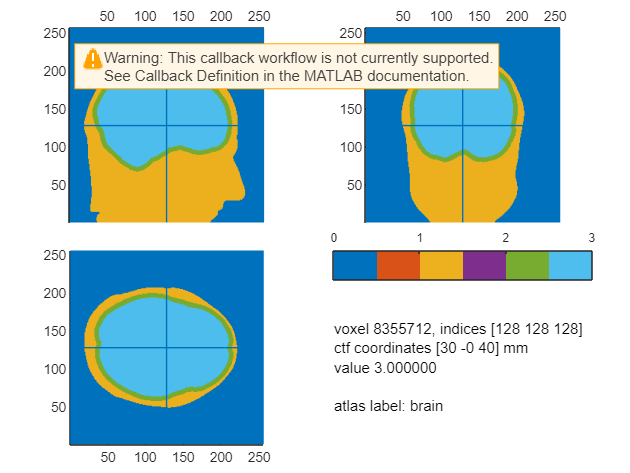


% Plot
% Extract indexes
mri_data_segmented_indexed_BEM = ft_datatype_segmentation(mri_data_segmented_BEM, 'segmentationstyle', 'indexed');

cfg = []; cfg.funparameter = 'tissue';
% cfg.funcolormap  = gray(5);
cfg.funcolormap  = lines(6);    
cfg.location     = 'center';
cfg.atlas        = mri_data_segmented_indexed_BEM;  
ft_sourceplot(cfg, mri_data_segmented_indexed_BEM); %The tissues are numbered according to the order in "tissuelabel"

From here, the mesh can be created, which is a triangulated description of the head from vertices connected with each other like triangles. Each triangle will be classified as one of the tissue category. 

The "mesh " variable is a structure composed of (1) the position of the vertices (in 3D: samples*x*y*z) and (2) the definition of each corner of a triangle (samples * nb_corners).

cfg = []; cfg.tissue = {'brain', 'skull', 'scalp'};
cfg.numvertices = [3000 2000 1000]; % ratio 3/2/1
mesh_mri_BEM = ft_prepare_mesh(cfg, mri_data_segmented_indexed_BEM);

converting tissue
creating probabilistic representation for scalp
creating probabilistic representation for skull
creating probabilistic representation for brain
triangulating the outer boundary of compartment 1 (brain) with 3000 vertices
triangulating the outer boundary of compartment 2 (skull) with 2000 vertices
triangulating the outer boundary of compartment 3 (scalp) with 1000 vertices
the call to "ft_prepare_mesh" took 4 seconds


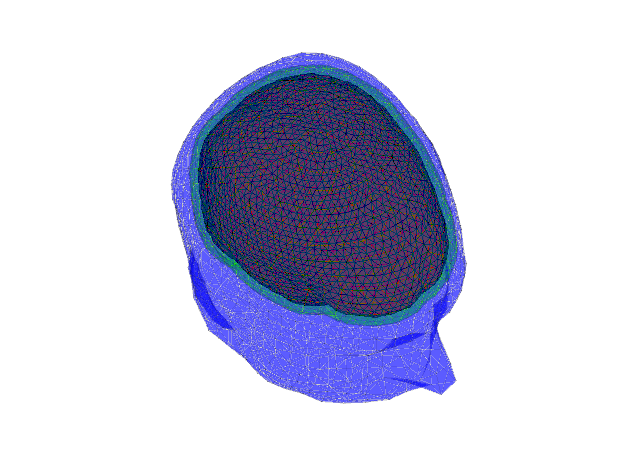


% Plot
figure
% Brain
ft_plot_mesh(mesh_mri_BEM(1), 'facecolor','r', 'facealpha', 1.0, 'edgecolor', 'k', 'edgealpha', 1);
hold on
% Skull
ft_plot_mesh(mesh_mri_BEM(2), 'facecolor','g', 'facealpha', 0.4, 'edgecolor', 'k', 'edgealpha', 0.1);
hold on
% Scalp
ft_plot_mesh(mesh_mri_BEM(3), 'facecolor','b', 'facealpha', 0.4, 'edgecolor', 'k', 'edgealpha', 0.1);
view(40,50)

The** volume conduction model (head model) **can be created. 

The head model is a struct array that contains information about (1) positions of the boundaries that is the same as the mesh, (2) the conductivities of the tissues, (3) the potential of every vertice.

cfg = []; cfg.method = 'bemcp'; headmodel_BEM  = ft_prepare_headmodel(cfg, mesh_mri_BEM);

 In ft_headmodel_bemcp at line 79
 In ft_prepare_headmodel at line 310

Nvert = 3000
Ntri = 5996
weight = 0.155225 , defl =  0.000000 
Nverta = 2000
Ntrib = 5996
Nverta = 3000
Ntrib = 3996
Nvert = 2000
Ntri = 3996
weight = -0.155225 , defl =  0.000000 
Nverta = 1000
Ntrib = 5996
Nverta = 1000
Ntrib = 3996
Nverta = 3000
Ntrib = 1996
Nverta = 2000
Ntrib = 1996
Nvert = 1000
Ntri = 1996
weight = 0.159155 , defl =  0.001000 
 In ft_prepare_headmodel at line 317

 In 


disp(headmodel_BEM)

             bnd: [1×3 struct]
            cond: [0.3300 0.0041 0.3300]
    skin_surface: 3
          source: 1
             mat: [1000×6000 double]
            type: 'bemcp'
            unit: 'mm'
             cfg: [1×1 struct]




% save headmodel_BEM headmodel_BEM

**Align with the electrodes**

elec_realigned = ft_read_sens('standard_1020.elc');

cfg = []; cfg.tissue = 'scalp';
cfg.numvertices = 10000;
mesh_scalp_BEM = ft_prepare_mesh(cfg, mri_data_segmented_BEM);

triangulating the outer boundary of compartment 1 (scalp) with 10000 vertices
the call to "ft_prepare_mesh" took 2 seconds



% Aligning with the scalp also aligns with lower structures
cfg = []; cfg.method = 'interactive';
cfg.elec = elec_realigned; cfg.headshape  = mesh_scalp_BEM;
elec_realigned = ft_electroderealign(cfg);

using electrodes specified in the configuration
Use the mouse to rotate the geometry, and click "redisplay" to update the light.
Close the figure when you are done.
orienting some EEG electrodes along the z-axis
the template coordinate system is "ctf"
the positive X-axis is pointing to anterior
the positive Y-axis is pointing to the left
the positive Z-axis is pointing to superior
the call to "ft_interactiverealign" took 132 seconds
the call to "ft_electroderealign" took 132 seconds


- Rotate -90 around z; apply

- Translate 35 along x and 35 along z; apply

- Scale 0.98 along x, 0.90 along y, and 0.80 along z; apply

- Translate 25 along z; apply

- Rotate 11 degrees around y; 

- Translate -5 along x; apply

- Quit

% save elec_realigned_BEM elec_realigned
% Plot
figure
ft_plot_headmodel(headmodel_BEM, 'facecolor', 'skin', 'edgecolor', 'brain','facealpha', 0.7);

this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


hold on
ft_plot_sens(elec_realigned, 'elecshape', 'sphere', 'label', 'on');

orienting some EEG electrodes along the z-axis


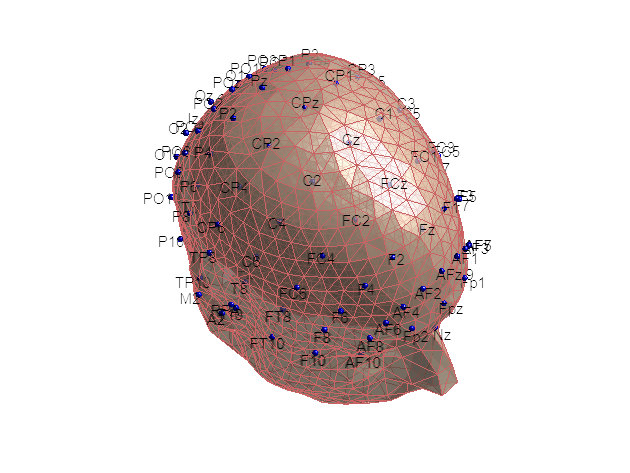

camlight
view(40,50)

Create the **source model.** Dipoles must be placed in the grey matter. 

cfg = []; cfg.resolution = 8; %cfg.threshold   = 0.1;
%cfg.smooth      = 5; 
cfg.headmodel   = headmodel_BEM;
cfg.inwardshift = 1; % shifts dipoles away from surfaces
sourcemodel_mri_BEM = ft_prepare_sourcemodel(cfg);

creating sourcemodel based on automatic 3D grid with specified resolution
creating 3D grid with 8 mm resolution
initial 3D grid dimensions are [29 24 32]
2866 dipoles inside, 19406 dipoles outside brain
making tight grid
2866 dipoles inside, 3118 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 1 seconds


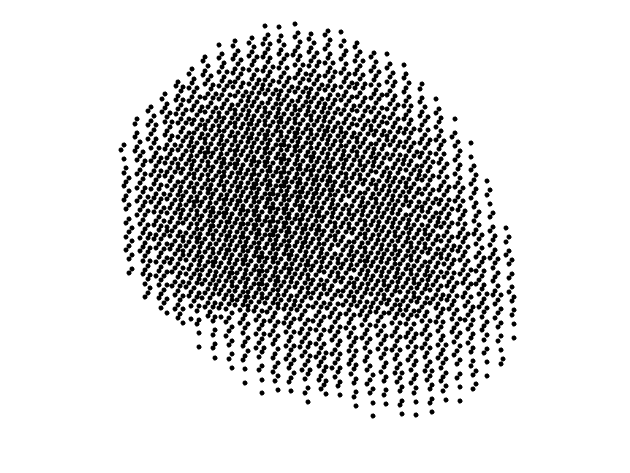


% Plot
figure()
ft_plot_mesh(sourcemodel_mri_BEM.pos(sourcemodel_mri_BEM.inside,:))
view(40, 50)

% Plot
figure()
ft_plot_mesh(sourcemodel_mri_BEM.pos(sourcemodel_mri_BEM.inside,:))
view(40,50)
hold on 
ft_plot_headmodel(headmodel_BEM, 'facecolor', 'skin', 'edgecolor', 'brain','facealpha', 0);

this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


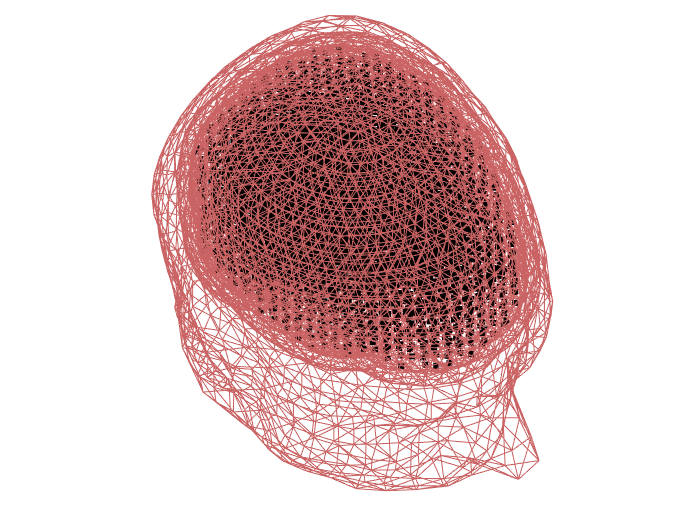

view(40, 50)

Select the sources that are in the grey matter

sourcemodel_mri_BEM.pos = sourcemodel_mri_BEM.pos(sourcemodel_mri_BEM.inside,:);
sourcemodel_mri_BEM.inside = sourcemodel_mri_BEM.inside(sourcemodel_mri_BEM.inside,:); 

Compute the** leadfield matrix**. It may be long, save the data for future use.

The leadfield is a structure composed of: 

- *dim: *dimensions of the grid (x*y*z)

- *pos: *position of the sources* (*x*y*z)

- *unit: *unit for position

- *inside: *1 the source is inside, 0: the source is outside 

- *leadfield: *each cell defines a source by a matrix of n_channels*x*y*z: potential measured at each electrode in its x*y*z orientation.

- *label:* electrodes

- *leadfielddimord*:each cell is a position (x*y*z) defined by a matrix corresponding to channels.

% compute the leadfield
cfg = []; cfg.grid = sourcemodel_mri_BEM;
cfg.headmodel= headmodel_BEM;
cfg.elec = elec_realigned;
cfg.reducerank = 3;
leadfield_mri_bem = ft_prepare_leadfield(cfg);

 In ft_checkconfig at line 130
 In ft_prepare_leadfield at line 137

using electrodes specified in the configuration
determining source compartment (1)
projecting electrodes on skin surface
combining electrode transfer and system matrix
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
2866 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds
computing leadfield
computing leadfield 2866/2866

the call to "ft_prepare_leadfield" took 6 seconds



% save leadfield_mri_bem leadfield_mri_bem 

disp(leadfield_mri_bem)

                dim: [22 16 17]
                pos: [2866×3 double]
               unit: 'mm'
             inside: [2866×1 logical]
                cfg: [1×1 struct]
          leadfield: {1×2866 cell}
              label: {97×1 cell}
    leadfielddimord: '{pos}_chan_ori'



### Finite Element Method (FEM)

clear; clc; close all; 
addpath(PathToFieldtrip); ft_defaults;

Here a dataset from Fieldtrip tutorials will be used. More information here: [https://www.fieldtriptoolbox.org/tutorial/meg_language/](https://www.fieldtriptoolbox.org/tutorial/meg_language/)

(Also, see all the datasets from Fieldtrip here: [https://www.fieldtriptoolbox.org/faq/datasets/)](https://www.fieldtriptoolbox.org/faq/datasets/))

mri_data = ft_read_mri('Subject01.mri');

 In ft_estimate_units at line 51
 In ft_determine_units at line 113
 In ft_read_mri at line 554



the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 0 seconds


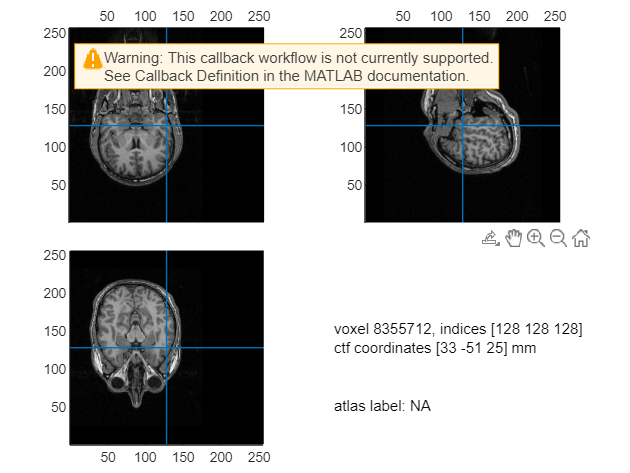

% Plot
cfg = []; cfg.method = 'ortho';
ft_sourceplot(cfg, mri_data)

Align the MRI coordinate to the EEG electrodes and source model.

The positive x-axis is pointing towards anterior
The positive y-axis is pointing towards the left
The positive z-axis is pointing towards superior
The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


ans = struct with fields:
          dim: [256 256 256]
      anatomy: [256×256×256 int16]
          hdr: [1×1 struct]
    transform: [4×4 double]
         unit: 'mm'
     coordsys: 'ctf'


% Check the coordinate system used by the MRI data
ft_determine_coordsys(mri_data)

% Here, the CTF system is used

% Realign: the positions of the LPA, RPA and nasion must be defined.

cfg = []; cfg.method = 'fiducial';
cfg.fiducial.nas = [87 60 116];
cfg.fiducial.lpa = [29 145 155];
cfg.fiducial.rpa = [144 142 158];
cfg.coordsys = 'ctf'; % the desired coordinate system
mri_data_realigned = ft_volumerealign(cfg, mri_data);

the input is volume data with dimensions [256 256 256]
the call to "ft_volumerealign" took 0 seconds


the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 0 seconds



% Plot
cfg = []; cfg.method = 'ortho'; ft_sourceplot(cfg, mri_data_realigned);

We see that the data is plotted upside down. The MRI image can be resliced: 

cfg = []; cfg.method = 'flip'; %linear
mri_data_resliced = ft_volumereslice(cfg, mri_data_realigned);

the input is volume data with dimensions [256 256 256]
 In getdimord>warning_dimord_could_not_be_determined at line 784
 In getdimord at line 734
 In ft_volumereslice at line 167

the call to "ft_volumereslice" took 0 seconds


the input is volume data with dimensions [256 256 256]
scaling anatomy to [0 1]
not plotting functional data
not applying a mask on the functional data
not using an atlas
not using a region-of-interest


 In ft_sourceplot>cb_redraw at line 1793
 In ft_sourceplot at line 1097

click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 0 seconds


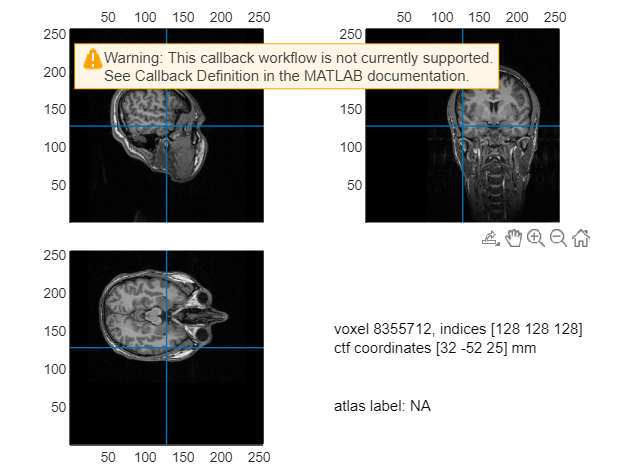

% Plot
cfg = []; cfg.method = 'ortho'; ft_sourceplot(cfg, mri_data_resliced)

For the FEM method, the data must now be segmented to differentiate the scalp, skull, cerebro-spinal fluid, gray, and white matters. Each voxel will be attributed to a structure. This step may be long to compute. It is recommended to save the data for future use.

cfg           = []; cfg.output    = {'gray', 'white', 'csf', 'skull', 'scalp'};
% cfg.brainsmooth    = 1; cfg.scalpthreshold = 0.11; cfg.skullthreshold = 0.15;
% cfg.brainthreshold = 0.15;
mri_data_segmented = ft_volumesegment(cfg, mri_data_resliced);

the input is volume data with dimensions [256 256 256]
using 'OldNorm' normalisation
Smoothing by 0 & 8mm..
Coarse Affine Registration..
Fine Affine Registration..
performing the segmentation on the specified volume, using the old-style segmentation

SPM12: spm_preproc (v4916)                         13:25:35 - 30/05/2024
Completed                               :          13:30:32 - 30/05/2024
creating scalpmask ... using the anatomy field for segmentation
smoothing anatomy with a 5-voxel FWHM kernel
thresholding anatomy at a relative threshold of 0.100
creating brainmask ... using the summation of gray, white and csf tpms
smoothing brainmask with a 5-voxel FWHM kernel
thresholding brainmask at a relative threshold of 0.500
creating skullmask ... using the brainmask
the call to "ft_volumesegment" took 331 seconds



% save mri_data_segmented_FEM mri_data_segmented

load('mri_data_segmented_FEM.mat')

% Visualization
disp(mri_data_segmented)

          dim: [256 256 256]
    transform: [4×4 double]
     coordsys: 'ctf'
         unit: 'mm'
         gray: [256×256×256 logical]
        white: [256×256×256 logical]
          csf: [256×256×256 logical]
        skull: [256×256×256 logical]
        scalp: [256×256×256 logical]
          cfg: [1×1 struct]




% Plot
% Extract indexes
mri_data_segmented_indexed = ft_datatype_segmentation(mri_data_segmented, 'segmentationstyle', 'indexed');

 In fixsegmentation at line 68
 In ft_datatype_segmentation at line 170



the input is segmented volume data with dimensions [256 256 256]
the volume of each of the segmented compartments in "tissue" is
csf             :      274 ml (  0.84 %)
gray            :      777 ml (  2.37 %)
scalp           :     2395 ml (  7.31 %)
skull           :      565 ml (  1.73 %)
white           :      485 ml (  1.48 %)
total segmented :     4496 ml ( 13.72 %)
total volume    :    32768 ml (100.00 %)
not plotting anatomy
not applying a mask on the functional data
not using a region-of-interest
click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 3 seconds


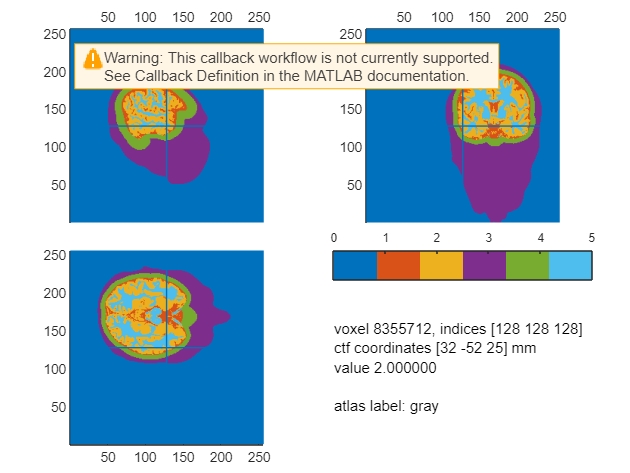


cfg = []; cfg.funparameter = 'tissue';
% cfg.funcolormap  = gray(5);
cfg.funcolormap  = lines(6);    
cfg.location     = 'center';
cfg.atlas        = mri_data_segmented_indexed;  
ft_sourceplot(cfg, mri_data_segmented_indexed); %The tissues are numbered according to the order in "tissuelabel"

From here, the mesh can be created, which is a hexahedral description of the head from 8 vertices connected with each other like cubles. Each hexahedron will be classified as one of the tissue category. 

The "mesh " variable is a structure composed of (1) the position of the vertices (in 3D: samples*x*y*z), (2) the definition of each corner of a hexahedron (samples * nb_corners), (3) the tissue assigned for each hexahedron, (4) labels of the tissues defined during segmentation, (5) the unit to express the vertices, (6) the coordinates system.

cfg = []; cfg.shift  = 0.3;
cfg.method = 'hexahedral';
% cfg.resolution = 1; % mm
mesh_mri = ft_prepare_mesh(cfg, mri_data_segmented);

 In fixsegmentation at line 68
 In ft_datatype_segmentation at line 170
 In ft_checkdata at line 285
 In prepare_mesh_hexahedral at line 18
 In ft_prepare_mesh at line 170

using the field "tissue" with the segmented tissue types cs


disp(mesh_mri)

            hex: [2301983×8 double]
            pos: [2372249×3 double]
         tissue: [2301983×1 double]
    tissuelabel: {'csf'  'gray'  'scalp'  'skull'  'white'}
           unit: 'mm'
       coordsys: 'ctf'
            cfg: [1×1 struct]




% save mesh_mri mesh_mri

load('mesh_mri.mat')

The** volume conduction model (head model) **can be created. 

The conductivities of each tissue must be defined following the order of labels of "mesh_mri.tissuelabel" (here, `'csf', 'gray', 'scalp', 'skull', 'white')`. 

The head model is a struct array that contains information about (1) pos, (2) hex, (3) tissue, (4) tissulabel, and (5) the unit also contained in the mesh, and (6) cond: the conductivity of every tissue, (7) stiff: sparse matrix of head model, and (8) type: the method used. 

cfg = []; cfg.method = 'simbio';
cfg.conductivity = [1.79 0.33 0.43 0.01 0.14];   
headmodel_mri  = ft_prepare_headmodel(cfg, mesh_mri);

the call to "ft_prepare_headmodel" took 34 seconds



disp(headmodel_mri)

            pos: [2372249×3 double]
            hex: [2301983×8 double]
         tissue: [2301983×1 double]
           cond: [1.7900 0.3300 0.4300 0.0100 0.1400]
    tissuelabel: {'csf'  'gray'  'scalp'  'skull'  'white'}
          stiff: [2372249×2372249 double]
           type: 'simbio'
           unit: 'mm'
            cfg: [1×1 struct]




% save headmodel_mri headmodel_mri

load('headmodel_mri')

% Plot the mesh
figure()
ft_plot_mesh(mesh_mri, 'edgecolor','none', 'facecolor', 'skin', 'facealpha', 0.7);

 In ft_plot_mesh at line 132

this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


ft_plot_axes(mesh_mri)

The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


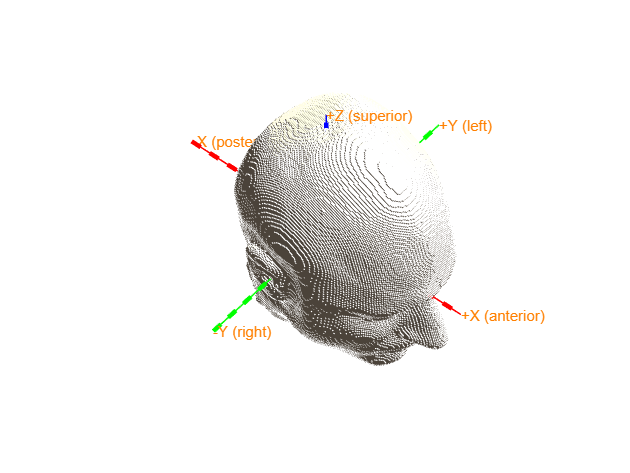

alpha 1
material default
camlight
view(40,50)

% Plot the mesh according to tissue
% Option 1
figure()
% make a copy for each tissue type
% after splitting we don't need the tissue and tissuelabel any more
mesh_mri_csf   = rmfield(mesh_mri, {'tissue', 'tissuelabel'});
mesh_mri_gray  = rmfield(mesh_mri, {'tissue', 'tissuelabel'});
mesh_mri_scalp = rmfield(mesh_mri, {'tissue', 'tissuelabel'});
mesh_mri_skull = rmfield(mesh_mri, {'tissue', 'tissuelabel'});
mesh_mri_white = rmfield(mesh_mri, {'tissue', 'tissuelabel'});

% only keep the hexahedra for the corresponding tissue type
mesh_mri_csf.hex   = mesh_mri.hex(mesh_mri.tissue==1,:);
mesh_mri_gray.hex  = mesh_mri.hex(mesh_mri.tissue==2,:);
mesh_mri_scalp.hex = mesh_mri.hex(mesh_mri.tissue==3,:);
mesh_mri_skull.hex = mesh_mri.hex(mesh_mri.tissue==4,:);
mesh_mri_white.hex = mesh_mri.hex(mesh_mri.tissue==5,:);

% Plot gray
ft_plot_mesh(mesh_mri_gray, 'edgecolor','none', 'facecolor', 'skin', 'facealpha', 0.7);

 In ft_plot_mesh at line 132



ft_plot_axes(mesh_mri_gray)

The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


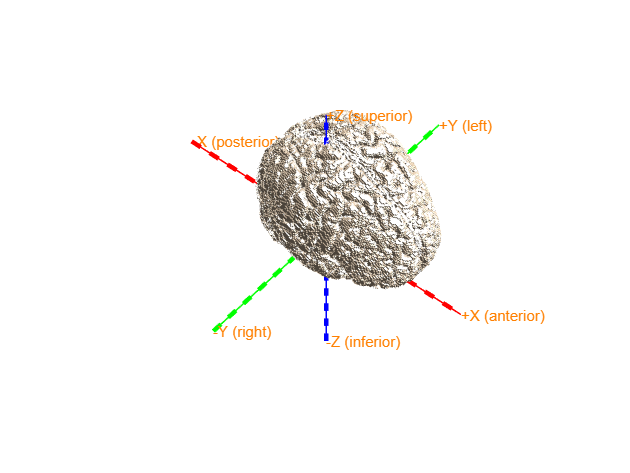

alpha 1
material default
camlight
view(40,50)

% Option 2 : you can see that the head model is not algined with the
% electrodes
figure()
elec_realigned = ft_read_sens('standard_1020.elc');

tissue_plot = 3; %scalp
mesh2 =[]; mesh2.hex = headmodel_mri.hex(headmodel_mri.tissue==tissue_plot,:);
mesh2.pos =  headmodel_mri.pos;
mesh2.tissue =  headmodel_mri.tissue(headmodel_mri.tissue==tissue_plot,:); 

mesh_ed = mesh2edge(mesh2);
patch('Faces',mesh_ed.poly,...
  'Vertices',mesh_ed.pos,...
  'FaceAlpha',.5,...
  'LineStyle', 'none',...
  'FaceColor',[1 1 1],...
  'FaceLighting', 'gouraud');

xlabel('coronal');ylabel('sagital');zlabel('axial');camlight;
axis on; ft_plot_sens(elec_realigned, 'style', '*g');

orienting some EEG electrodes along the z-axis


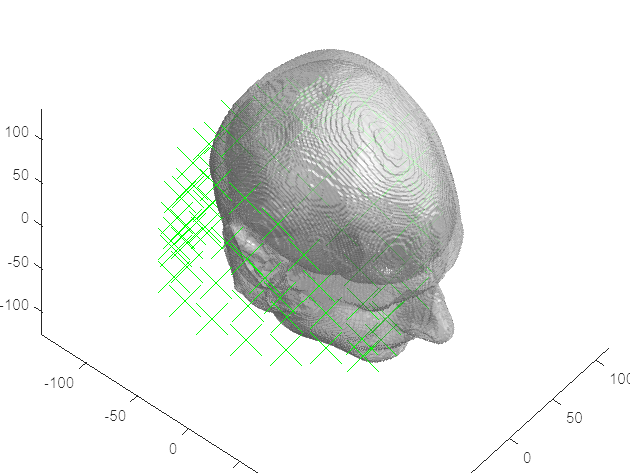

view(40,50)

**Align with the electrodes**

elec_realigned = ft_read_sens('standard_1020.elc');

cfg = [];
cfg.method = 'interactive';
cfg.headshape = mesh_mri; % we can specify the hexahedral FEM mesh as the headshape
elec_realigned = ft_electroderealign(cfg, elec_realigned)

extracting surface from hexahedral mesh
Use the mouse to rotate the geometry, and click "redisplay" to update the light.
Close the figure when you are done.
orienting some EEG electrodes along the z-axis


 In ft_plot_mesh at line 132
 In ft_plot_headshape at line 102
 In ft_interactiverealign>cb_redraw at line 403
 In ft_interactiverealign at line 208
 In ft_electroderealign at line 574

the template coordinate system is "ctf"
the positive X-axis is pointing

elec_realigned = struct with fields:
        chanpos: [97×3 double]
       chantype: {97×1 cell}
       chanunit: {97×1 cell}
        elecpos: [97×3 double]
    homogeneous: [4×4 double]
          label: {97×1 cell}
            tra: [97×97 double]
           type: 'eeg1010'
           unit: 'mm'
            cfg: [1×1 struct]


- Rotate -90 around z; apply

- Translate 35 along x and 35 along z; apply

- Scale 0.98 along x, 0.90 along y, and 0.80 along z; apply

- Translate 25 along z; apply

- Rotate 11 degrees around y; 

- Translate -5 along x; apply

- Quit

% Option 1
figure()
ft_plot_headmodel(headmodel_mri, 'facecolor', 'skin', 'edgecolor', 'brain','facealpha', 0.7);

this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


hold on
ft_plot_sens(elec_realigned, 'elecshape', 'sphere', 'label', 'on');

orienting some EEG electrodes along the z-axis


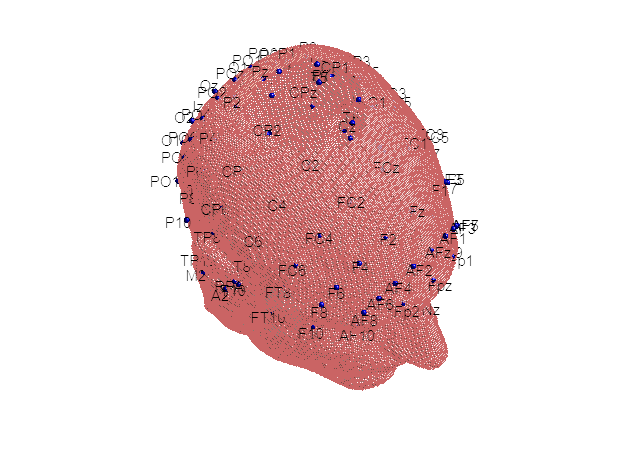

camlight
view(40,50)


% Option 2
figure()
tissue_plot = 3; %scalp
mesh2 =[]; mesh2.hex = headmodel_mri.hex(headmodel_mri.tissue==tissue_plot,:);
mesh2.pos =  headmodel_mri.pos;
mesh2.tissue =  headmodel_mri.tissue(headmodel_mri.tissue==tissue_plot,:); 

mesh_ed = mesh2edge(mesh2);
patch('Faces',mesh_ed.poly,...
  'Vertices',mesh_ed.pos,...
  'FaceAlpha',.5,...
  'LineStyle', 'none',...
  'FaceColor',[1 1 1],...
  'FaceLighting', 'gouraud');

xlabel('coronal'); ylabel('sagital'); zlabel('axial')
camlight; axis on;ft_plot_sens(elec_realigned, 'style', '*g');

orienting some EEG electrodes along the z-axis


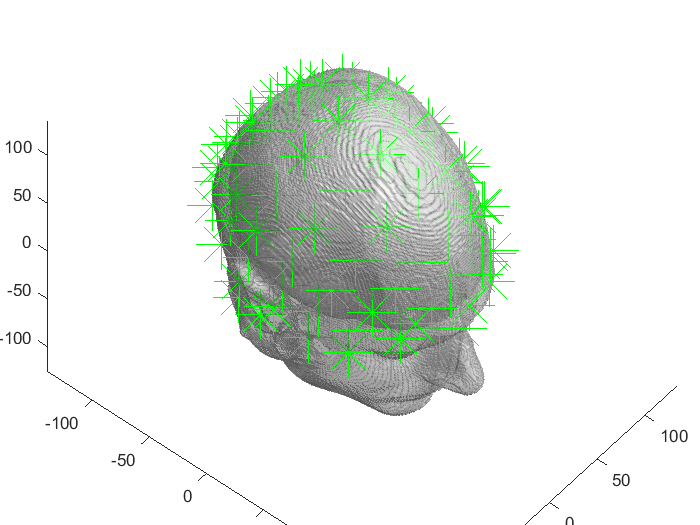

view(40,50)

Create the **source model.** Dipoles must be placed in the grey matter. 

% cfg = []; cfg.method = 'basedonresolution';
% cfg.resolution = 8; 
% cfg.unit = 'mm'; cfg.headmodel = mesh_mri;
% cfg.headmodel.type = 'simbio'; cfg.movetocentroids = 'yes';
% % Dipoles are moved to the centroids of the volume elements
% sourcemodel_mri = ft_prepare_sourcemodel(cfg)

% Specify the initial 3D grid for less computation time.
% Approximate bounderies of the brain must be known.

% cfg = []; cfg.method = 'basedongrid';
% cfg.xgrid = -80:8:120;  % multiples of 8
% cfg.ygrid = -80:8:80; cfg.zgrid = -24:8:120;
% cfg.unit = 'mm'; cfg.headmodel = mesh_mri;
% cfg.headmodel.type = 'simbio'; cfg.movetocentroids = 'yes';
% sourcemodel_mri = ft_prepare_sourcemodel(cfg)

cfg = []; cfg.resolution = 8; %cfg.threshold   = 0.1;
%cfg.smooth      = 5; 
cfg.headmodel   = headmodel_mri;
cfg.inwardshift = 1; % shifts dipoles away from surfaces
sourcemodel_mri = ft_prepare_sourcemodel(cfg);

creating sourcemodel based on automatic 3D grid with specified resolution
creating 3D grid with 8 mm resolution
initial 3D grid dimensions are [31 24 37]
selecting dipole positions inside the 'gray' tissue
pruning headmodel volume elements from 2301983 to 397830 (17%)
pruning headmodel vertices from 2372249 to 583565 (25%)
pruning dipole positions from 27528 to 5984 (22%)
1554 dipoles inside, 25974 dipoles outside brain
making tight grid
1554 dipoles inside, 4430 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 2 seconds


% Plot the sources: only grey matter
figure()
ft_plot_mesh(sourcemodel_mri.pos(sourcemodel_mri.inside,:))
hold on, 
ft_plot_mesh(mesh_mri, 'surfaceonly', 'yes', 'vertexcolor', 'none', 'facecolor',...
           'skin', 'facealpha',0.5, 'edgealpha',0.1)

this returns a light skin, you can also explicitly specify 'skin_light',' skin_medium_light', 'skin_medium', 'skin_medium_dark', or 'skin_dark'


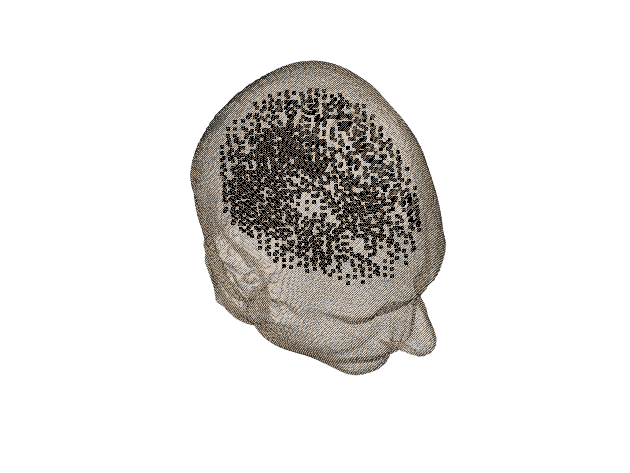


view(40,50)

% Plot the sources: Whole source model. There is a lot of dipoles outside
% the grey matter 
figure()
ft_plot_mesh(sourcemodel_mri); ft_plot_axes(sourcemodel_mri)

The axes are 150 mm long in each direction
The diameter of the sphere at the origin is 10 mm


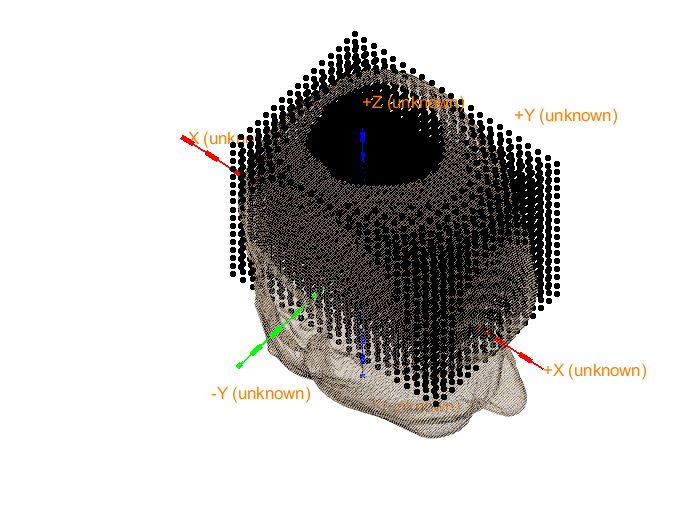

hold on, 
ft_plot_mesh(mesh_mri, 'surfaceonly', 'yes', 'vertexcolor', 'none', 'facecolor',...
       'skin', 'facealpha',0.5, 'edgealpha',0.1)
view(40,50) 

Select the sources that are in the grey matter

sourcemodel_mri.pos = sourcemodel_mri.pos(sourcemodel_mri.inside,:);
sourcemodel_mri.inside = sourcemodel_mri.inside(sourcemodel_mri.inside,:); 

Compute the** leadfield matrix**. It may be long, save the data for future use.

The leadfield is a structure composed of: 

- *dim: *dimensions of the grid (x*y*z)

- *pos: *position of the sources* (*x*y*z)

- *unit: *unit for position

- *inside: *1 the source is inside, 0: the source is outside 

- *leadfield: *each cell defines a source by a matrix of n_channels*x*y*z: potential measured at each electrode in its x*y*z orientation.

- *label:* electrodes

- *leadfielddimord*:each cell is a position (x*y*z) defined by a matrix corresponding to channels.

% transfer matrix
[headmodel_mri, elec_realigned] = ft_prepare_vol_sens(headmodel_mri, elec_realigned);

Find electrode positions...
Calculate transfer matrix...
Electrode 2 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5008e-09

Electrode 3 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7363e-09

Electrode 4 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6526e-09

Electrode 5 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0181e-09

Electrode 6 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2729e-09

Electrode 7 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9899e-09

Electrode 8 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6933e-09

Electrode 9 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9075e-09

Electrode 10 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4141e-09

Electrode 11 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0756e-09

Electrode 12 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2423e-09

Electrode 13 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5747e-09

Electrode 14 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4460e-09

Electrode 15 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9580e-09

Electrode 16 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6332e-09

Electrode 17 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8360e-09

Electrode 18 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5470e-09

Electrode 19 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9959e-09

Electrode 20 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1986e-09

Electrode 21 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2483e-09

Electrode 22 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4427e-09

Electrode 23 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2825e-09

Electrode 24 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5995e-09

Electrode 25 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8788e-09

Electrode 26 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0498e-09

Electrode 27 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1680e-09

Electrode 28 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8647e-09

Electrode 29 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7906e-09

Electrode 30 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8573e-09

Electrode 31 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9174e-09

Electrode 32 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9187e-09

Electrode 33 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2750e-09

Electrode 34 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8967e-09

Electrode 35 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9410e-09

Electrode 36 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6301e-09

Electrode 37 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0660e-09

Electrode 38 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7893e-09

Electrode 39 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9287e-09

Electrode 40 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5346e-09

Electrode 41 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1313e-09

Electrode 42 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6882e-09

Electrode 43 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7847e-09

Electrode 44 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6496e-09

Electrode 45 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7844e-09

Electrode 46 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7584e-09

Electrode 47 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3385e-09

Electrode 48 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8302e-09

Electrode 49 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0776e-09

Electrode 50 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5446e-09

Electrode 51 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9385e-09

Electrode 52 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2488e-09

Electrode 53 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6002e-09

Electrode 54 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0632e-09

Electrode 55 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8204e-09

Electrode 56 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4906e-09

Electrode 57 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4504e-09

Electrode 58 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6076e-09

Electrode 59 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1741e-09

Electrode 60 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7333e-09

Electrode 61 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3756e-09

Electrode 62 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5660e-09

Electrode 63 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1005e-09

Electrode 64 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6502e-09

Electrode 65 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4995e-09

Electrode 66 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7286e-09

Electrode 67 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6012e-09

Electrode 68 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4959e-09

Electrode 69 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2120e-09

Electrode 70 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3961e-09

Electrode 71 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3528e-09

Electrode 72 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9246e-09

Electrode 73 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8051e-09

Electrode 74 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3297e-09

Electrode 75 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.9870e-09

Electrode 76 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7050e-09

Electrode 77 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.8693e-09

Electrode 78 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6433e-09

Electrode 79 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4049e-09

Electrode 80 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9395e-09

Electrode 81 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.5635e-09

Electrode 82 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1408e-09

Electrode 83 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7920e-09

Electrode 84 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2635e-09

Electrode 85 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.7693e-09

Electrode 86 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.6765e-09

Electrode 87 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3224e-09

Electrode 88 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.6645e-09

Electrode 89 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.2071e-09

Electrode 90 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1313e-09

Electrode 91 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.1005e-09

Electrode 92 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.0776e-09

Electrode 93 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.3528e-09

Electrode 94 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4584e-09

Electrode 95 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.9626e-09

Electrode 96 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 8.8447e-09

Electrode 97 of 97
Scaling stiffnes matrix...
Preconditioning...
Finding startvector...
Solving equation system...


rr = 9.4512e-09


% compute the leadfield
cfg = []; cfg.grid = sourcemodel_mri;
cfg.headmodel= headmodel_mri;
cfg.elec = elec_realigned;
cfg.reducerank = 3;
leadfield_mri_fem = ft_prepare_leadfield(cfg);

 In ft_checkconfig at line 130
 In ft_prepare_leadfield at line 137

using electrodes specified in the configuration
creating sourcemodel based on user specified dipole positions
using electrodes specified in the configuration
1554 dipoles inside, 0 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 1 seconds
computing leadfield
computing leadfield 1554/1554

the call to "ft_prepare_leadfield" took 269 seconds



% save leadfield_mri_fem leadfield_mri_fem 

disp(leadfield_mri_fem)

                dim: [22 16 17]
                pos: [1554×3 double]
               unit: 'mm'
             inside: [1554×1 logical]
                cfg: [1×1 struct]
          leadfield: {1×1554 cell}
              label: {97×1 cell}
    leadfielddimord: '{pos}_chan_ori'



### Source reconstruction of event-related potentials

#### Minimum-norm estimation

Generally applied to wide-spread cortical activity and assumes a large number of dipoles. 

#### Goal 

A representation of the neuronal activity underlying event-related components that resulted in the topography of the activity observed at the sensors is calculated.

Here, the activity of the source of the ERP computed in the "*EventRelatedPotentials.mlx*" document will be extracted.

load('EEG_epoched_filt.mat')

% Cond1 - participant 1
EEG_cond1 = struct(); EEG_cond1.label = {EEG_epoched_filt{1,1}.chanlocs.labels}';

data = EEG_epoched_filt{1,1}.data; 
for i = 1:1:size(data,3)
    EEG_cond1_trial{1,i} = data(:,:,i);
    EEG_cond1_time{1,i} = EEG_epoched_filt{1,1}.times;
end

EEG_cond1.trial = EEG_cond1_trial; EEG_cond1.time =  EEG_cond1_time;
EEG_cond1.fsample = EEG_epoched_filt{1,1}.srate;

% Cond2 - participant 1
EEG_cond2 = struct(); EEG_cond2.label = {EEG_epoched_filt{2,1}.chanlocs.labels}';

data = EEG_epoched_filt{2,1}.data; 
for i = 1:1:size(data,3)
    EEG_cond1_trial{1,i} = data(:,:,i);
    EEG_cond1_time{1,i} = EEG_epoched_filt{2,1}.times;
end

EEG_cond2.trial = EEG_cond1_trial; EEG_cond2.time =  EEG_cond1_time;
EEG_cond2.fsample = EEG_epoched_filt{2,1}.srate;

% Average over trials 
cfg = []; cfg.covariance = 'yes'; cfg.covariancewindow = [-inf 0]; 
avgCond1 = ft_timelockanalysis(cfg, EEG_cond1);

the input is raw data with 24 channels and 240 trials
 In fixsampleinfo at line 92
 In ft_datatype_raw at line 148
 In ft_checkdata at line 277
 In ft_timelockanalysis at line 98

 In fixsampleinfo at line 105
 In 

avgCond2 = ft_timelockanalysis(cfg, EEG_cond2);

the input is raw data with 24 channels and 240 trials
 In fixsampleinfo at line 92
 In ft_datatype_raw at line 148
 In ft_checkdata at line 277
 In ft_timelockanalysis at line 98

 In fixsampleinfo at line 105
 In 

Inverse solution - Minimum-norm estimation - from FEM

% The output avg.pow contains the activity of the source through time 
load('leadfield_mri_fem.mat'); leadfield_mri_fem.label = avgCond2.label; load('headmodel_mri.mat');
cfg = []; cfg.method = 'mne'; cfg.grid = leadfield_mri_fem; cfg.headmodel = headmodel_mri;
cfg.mne.prewhiten = 'yes'; cfg.mne.lambda = 3;  %scaling to the noise variance
cfg.mne.scalesourcecov = 'yes';
sourceCond1 = ft_sourceanalysis(cfg,avgCond1); sourceCond2= ft_sourceanalysis(cfg, avgCond2);

the input is timelock data with 24 channels and 375 timebins


 In ft_checkconfig at line 130
 In ft_sourceanalysis at line 192

the call to "ft_selectdata" took 0 seconds
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds
estimating current density distribution for repetition 1
using precomputed leadfields
computing the solution where the noise covariance is used for regularisation
prewhitening the leadfields using the noise covariance
scaling the source covariance
The input data are real-valued, assuming sensor time-series: Computing the dipole moments
the call to "ft_sourceanalysis" took 0 seconds
the input is timelock data with 24 channels and 375 timebins


 In ft_checkconfig at line 130
 In ft_sourceanalysis at line 192

the call to "ft_selectdata" took 0 seconds
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds
estimating current density distribution for repetition 1
using precomputed leadfields
computing the solution where the noise covariance is used for regularisation
prewhitening the leadfields using the noise covariance
scaling the source covariance
The input data are real-valued, assuming sensor time-series: Computing the dipole moments
the call to "ft_sourceanalysis" took 0 seconds


Inverse solution - Minimum-norm estimation - from BEM

% The output avg.pow contains the activity of the source through time 
load('leadfield_mri_bem.mat'); leadfield_mri_bem.label = avgCond2.label; load('headmodel_BEM.mat');
cfg = []; cfg.method = 'mne'; cfg.grid = leadfield_mri_bem; cfg.headmodel = headmodel_BEM;
cfg.mne.prewhiten = 'yes'; cfg.mne.lambda = 3;  %scaling to the noise variance
cfg.mne.scalesourcecov = 'yes';
sourceCond1 = ft_sourceanalysis(cfg,avgCond1); sourceCond2= ft_sourceanalysis(cfg, avgCond2);

the input is timelock data with 24 channels and 375 timebins


 In ft_checkconfig at line 130
 In ft_sourceanalysis at line 192

the call to "ft_selectdata" took 0 seconds
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds
estimating current density distribution for repetition 1
using precomputed leadfields
computing the solution where the noise covariance is used for regularisation
prewhitening the leadfields using the noise covariance
scaling the source covariance
The input data are real-valued, assuming sensor time-series: Computing the dipole moments
the call to "ft_sourceanalysis" took 0 seconds
the input is timelock data with 24 channels and 375 timebins


 In ft_checkconfig at line 130
 In ft_sourceanalysis at line 192

the call to "ft_selectdata" took 0 seconds
using precomputed leadfields
the call to "ft_selectdata" took 0 seconds
estimating current density distribution for repetition 1
using precomputed leadfields
computing the solution where the noise covariance is used for regularisation
prewhitening the leadfields using the noise covariance
scaling the source covariance
The input data are real-valued, assuming sensor time-series: Computing the dipole moments
the call to "ft_sourceanalysis" took 0 seconds


### References

Most of the codes and presented above are inspired by the tutorials available through the followoing links:

[https://eeglab.org/tutorials/09_source/](https://eeglab.org/tutorials/09_source/)

[https://www.fieldtriptoolbox.org/workshop/ohbm2018/forward/](https://www.fieldtriptoolbox.org/workshop/ohbm2018/forward/)

[https://www.fieldtriptoolbox.org/workshop/baci2017/forwardproblem/#b-finite-element-method-fem](https://www.fieldtriptoolbox.org/workshop/baci2017/forwardproblem/#b-finite-element-method-fem)

[https://www.fieldtriptoolbox.org/tutorial/headmodel_eeg_fem/](https://www.fieldtriptoolbox.org/tutorial/headmodel_eeg_fem/)

[https://www.fieldtriptoolbox.org/tutorial/headmodel_eeg_bem/](https://www.fieldtriptoolbox.org/tutorial/headmodel_eeg_bem/)

[https://www.fieldtriptoolbox.org/workshop/ohbm2018/inverse/#minimum-norm-estimate](https://www.fieldtriptoolbox.org/workshop/ohbm2018/inverse/#minimum-norm-estimate)

[https://www.fieldtriptoolbox.org/tutorial/minimumnormestimate/](https://www.fieldtriptoolbox.org/tutorial/minimumnormestimate/)

[https://www.fieldtriptoolbox.org/workshop/oslo2019/forward_modeling/](https://www.fieldtriptoolbox.org/workshop/oslo2019/forward_modeling/)

Data from Subject01 are available at: 

[https://download.fieldtriptoolbox.org/tutorial/headmodel_eeg_fem/](https://download.fieldtriptoolbox.org/tutorial/headmodel_eeg_fem/)